%calculating the mean first passage time analytically/numerically 
%to investigate effect of incumbent-substrate mismatch position on DNA/RNA
%TMSD kinetics including spontaneous incumbent dissociation

b = 20 %define branch migration domain length

b = 20

g = 4 %define invader toehold length

g = 4


R = 1.987/1000 %universal gas constant in kcal/K/mol 

R = 0.0020

temp = 298.15 %temperature in K

temp = 298.1500

%free energy parameter
dGassoc = 2.6*R*temp 

dGassoc = 1.5403

dGbp = -2.52*R*temp

dGbp = -1.4929

dGp = 3.6*R*temp

dGp = 2.1327

dGrd = -0.2*R*temp

dGrd = -0.1185

dGmm = 9.5*R*temp

dGmm = 5.6280

dGbm = 7.4*R*temp

dGbm = 4.3839

%absolute rate constant
k_bp = 5.4*10^7

k_bp = 54000000

k_eff = zeros(1,19)

k_eff =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time = zeros(1, 19)

first_pass_time =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


prob_unbound = zeros(1, 19)

prob_unbound =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


k_eff_perf = zeros(1, 19)

k_eff_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time_perf = zeros(1, 19)

first_pass_time_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


prob_unbound_perf = zeros(1, 19)

prob_unbound_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0



dGbox_avr = zeros(19, b-1)

dGbox_avr =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0  


%loop through mismatch position 
for m = 1:19
    
    %loop through states prior to mismatch (in branch migration domain) and
    %define free energy
    for state = 1:m-1
        dGbox_avr(m, state) = - R*temp*log(exp(-((-dGbp-dGrd)*(m - state) + (m)*-dGrd + dGp)/(R*temp)) + exp(-(dGmm+(m-state)*(dGrd) + (m)*-dGrd + dGp)/(R*temp))) 
    end
    
    %define free energy of states after mismatch
    dGbox_avr(m, 1:m) = horzcat(dGbox_avr(m, 1:m-1), dGp - (m)*dGrd)
    
    %define free energy of final state in invader toehold 
    dGboxC1 = -R*temp*log(exp(-((-dGbp-dGrd)*(m - 0)+ (m)*-dGrd + dGp)/(R*temp)) + exp(-(dGmm)/(R*temp))) 
    
    trans_state = (-dGbp - dGrd)*(b - 1)
    react_coord = zeros(1, b-1)
    %loop through states prior to mismatch and define free energy (in terms
    %of incumbent dissociation)
    for state = 1:m-1
        react_coord(state) = -R*temp*log(exp(-(state*(-dGbp-dGrd) + dGmm)/(R*temp)) + exp(-(state*(-dGbp-dGrd))/(R*temp)))
    end
    %loop through states after mismatch and define free energy (in terms of
    %incumbent dissociation)
    for state = m:b-1
        react_coord(state) = state*(-dGbp - dGrd)
    end
    react_coord = flip(react_coord);
    
    %define forward and reverse transition rates 
    k_AA = 0;
    k_AB1 = k_bp * exp(-dGassoc/(R*temp)) * (5*10^-8)
    k_B1A = k_bp * exp(dGbp/(R*temp))
    k_BC1ij = k_bp;
    k_BC1ji = k_bp * exp(dGbp/(R*temp));
    k_C1f = k_bp * exp(-(dGbm + dGp - dGrd)/(R*temp))
    k_C1fm = k_bp * exp(-(dGbm + dGbox_avr(m, 1) -dGboxC1)/(R*temp))
    k_Cf = k_bp * exp(-(dGbm - dGrd)/(R*temp))
    k_Cfbm = zeros(1, m-2);
    for state = 2:m
        k_Cfbm(state-1) = k_bp * exp(-(dGbox_avr(m, state) - dGbox_avr(m, state-1) + dGbm)/(R*temp))
    end
    k_Cr = k_bp * exp(-dGbm/(R*temp));
    k_CD = k_bp * exp(-(dGbm - dGrd)/(R*temp));
    k_DC = 0 
    k_DD = 1
    
    %create arrays of forward and reverse transition rates for
    %mismatch-free system
    Kf_perf = [k_DD, k_CD, repmat(k_Cf, [1, b-2]), k_C1f, repmat(k_BC1ij, [1, g-2]), k_BC1ij, k_AB1]
    Kb_perf = [k_DC, repmat(k_Cr, [1, b-2]), k_Cr, k_BC1ji, repmat(k_BC1ji, [1, g-2]), k_B1A, k_AA]
    
    %define spontaneous incumbent dissociation rates for mismatch-free
    %system
    Koff_perf = [0]; 
    for n = 1:b-1
        Koff_perf = horzcat(Koff_perf, [k_bp*exp(-(n*(-dGbp - dGrd))/(R*temp))]);
    end
    Koff_perf = horzcat(Koff_perf, [repmat(0, [1, g+1])])
    
    if g == 1
        %create arrays of forward and reverse transition rates for mismatch
        %system
        Kf = [k_DD, k_CD, repmat(k_Cf, [1, b-2]), k_C1f, k_AB1]
        Kb = [k_DC, repmat(k_Cr, [1, b-2]), k_Cr, k_B1A, k_AA]
        
        %define spontaneous incumbent dissociation rates for mismatch
        %system
        Koff = [0];
        for n = 1:b-1
            Koff = horzcat(Koff, [k_bp*exp(-(-dGbp - dGrd)/(R*temp))*exp(-(trans_state - react_coord(n))/(R*temp))]);
        end
        Koff = horzcat(Koff, [0, 0])
        
    else
        %create arrays of forward and reverse transition rates for mismatch
        %system
        Kf = [k_DD, k_CD, repmat(k_Cf, [1, b-m-1]), flip(k_Cfbm), k_C1fm, repmat(k_BC1ij, [1, g-2]), k_BC1ij, k_AB1]
        Kb = [k_DC, repmat(k_Cr, [1, b-2]), k_Cr, k_BC1ji, repmat(k_BC1ji, [1, g-2]), k_B1A, k_AA]
    
        %define spontaneous incumbent dissociation rates for mismatch
        %system
        Koff = [0]; 
        for n = 1:b-1
            Koff = horzcat(Koff, [k_bp*exp(-(-dGbp - dGrd)/(R*temp))*exp(-(trans_state - react_coord(n))/(R*temp))]);
        end
        Koff = horzcat(Koff, [repmat(0, [1, g+1])])
    end
    
    Pn_jN_1 = zeros(1,numel(Kf))
    jn_jN_1 = zeros(1,numel(Kf))
    Pn_jN_1 (1) = 0;
    jn_jN_1 (1) = 1;
        
    %calculate flux between each state for mismatch system
    for Pn = 2:numel(Kf)
        Pn_jN_1(Pn)  = 1/Kf(Pn) * jn_jN_1 (Pn-1) + (Kb(Pn-1)/Kf(Pn))*Pn_jN_1(Pn-1);
        jn_jN_1(Pn) = jn_jN_1(Pn-1) + Koff(Pn) * Pn_jN_1(Pn);
    end
        
    Pn_jN_1_perf = zeros(1,numel(Kf_perf))
    jn_jN_1_perf = zeros(1,numel(Kf_perf))
    Pn_jN_1_perf (1) = 0;
    jn_jN_1_perf (1) = 1;
        
    %calculate flux between each state for mismatch-free system
    for Pn = 2:numel(Kf_perf)
        Pn_jN_1_perf(Pn)  = 1/Kf_perf(Pn) * jn_jN_1_perf (Pn-1) + (Kb_perf(Pn-1)/Kf_perf(Pn))*Pn_jN_1_perf(Pn-1);
        jn_jN_1_perf(Pn) = jn_jN_1_perf(Pn-1) + Koff_perf(Pn) * Pn_jN_1_perf(Pn);
    end
    
    first_pass_time (m) = (1/jn_jN_1(end-1))*sum(Pn_jN_1) %first passage time for mismatch system
    k_eff (m) = 1/(first_pass_time (m)*(5*10^-8)); %effective rate constant for mismatch system
    prob_unbound(m) = Pn_jN_1(end)/sum(Pn_jN_1) %probability of being in unbound state for mismatch system
    
    first_pass_time_perf (m) = (1/jn_jN_1_perf(end-1))*sum(Pn_jN_1_perf) %first passage time for mismatch-free system
    k_eff_perf (m) = 1/(first_pass_time_perf (m)*(5*10^-8)); %effective rate constant for mismatch-free system
    prob_unbound_perf(m) = Pn_jN_1_perf(end)/sum(Pn_jN_1_perf) %probability of being in unbound state for mismatch-free system
end

dGbox_avr =     2.2512         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0   

dGboxC1 = 3.8333

trans_state = 30.6165

react_coord =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


react_coord =     1.6114         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.6114    3.2228         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.6114    3.2228    4.8342         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.6114    3.2228    4.8342    6.4456         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.6114    3.2228    4.8342    6.4456    8.0570         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.6114    3.2228    4.8342    6.4456    8.0570    9.6684         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.6114    3.2228    4.8342    6.4456    8.0570    9.6684   11.2798         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.6114    3.2228    4.8342    6.4456    8.0570    9.6684   11.2798   12.8911         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.6114    3.2228    4.8342    6.4456    8.0570    9.6684   11.2798   12.8911   14.5025         0         0         0         0         0         0         0         0         0         0


react_coord =     1.6114    3.2228    4.8342    6.4456    8.0570    9.6684   11.2798   12.8911   14.5025   16.1139         0         0         0         0         0         0         0         0         0


react_coord =     1.6114    3.2228    4.8342    6.4456    8.0570    9.6684   11.2798   12.8911   14.5025   16.1139   17.7253         0         0         0         0         0         0         0         0


react_coord =     1.6114    3.2228    4.8342    6.4456    8.0570    9.6684   11.2798   12.8911   14.5025   16.1139   17.7253   19.3367         0         0         0         0         0         0         0


react_coord =     1.6114    3.2228    4.8342    6.4456    8.0570    9.6684   11.2798   12.8911   14.5025   16.1139   17.7253   19.3367   20.9481         0         0         0         0         0         0


react_coord =     1.6114    3.2228    4.8342    6.4456    8.0570    9.6684   11.2798   12.8911   14.5025   16.1139   17.7253   19.3367   20.9481   22.5595         0         0         0         0         0


react_coord =     1.6114    3.2228    4.8342    6.4456    8.0570    9.6684   11.2798   12.8911   14.5025   16.1139   17.7253   19.3367   20.9481   22.5595   24.1709         0         0         0         0


react_coord =     1.6114    3.2228    4.8342    6.4456    8.0570    9.6684   11.2798   12.8911   14.5025   16.1139   17.7253   19.3367   20.9481   22.5595   24.1709   25.7823         0         0         0


react_coord =     1.6114    3.2228    4.8342    6.4456    8.0570    9.6684   11.2798   12.8911   14.5025   16.1139   17.7253   19.3367   20.9481   22.5595   24.1709   25.7823   27.3937         0         0


react_coord =     1.6114    3.2228    4.8342    6.4456    8.0570    9.6684   11.2798   12.8911   14.5025   16.1139   17.7253   19.3367   20.9481   22.5595   24.1709   25.7823   27.3937   29.0051         0


react_coord =     1.6114    3.2228    4.8342    6.4456    8.0570    9.6684   11.2798   12.8911   14.5025   16.1139   17.7253   19.3367   20.9481   22.5595   24.1709   25.7823   27.3937   29.0051   30.6165


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 738.4066

k_C1fm = 4.7685e+05

k_Cf = 2.7024e+04

k_DC = 0

k_DD = 1

Kf_perf = 	1.0e+07 *

    0.0000    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0001    5.4000    5.4000    5.4000    0.0000


Kb_perf = 	1.0e+06 *

         0    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    4.3448    4.3448    4.3448    4.3448         0


Koff_perf = 	1.0e+06 *

         0    3.5572    0.2343    0.0154    0.0010    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0


Kf = 	1.0e+07 *

    0.0000    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0477    5.4000    5.4000    5.4000    0.0000


Kb = 	1.0e+06 *

         0    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    4.3448    4.3448    4.3448    4.3448         0


Koff = 	1.0e+06 *

         0    3.5572    0.2343    0.0154    0.0010    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     8.9451         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     0.9975         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


first_pass_time_perf = 	1.0e+03 *

    2.2661         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound_perf =     0.9999         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


dGbox_avr =     2.2512         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    3.9803         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0   

dGbox_avr =     2.2512         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    3.9803    2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0   

dGboxC1 = 5.1994

trans_state = 30.6165

react_coord =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


react_coord =     1.6113         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.6113    3.2228         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.6113    3.2228    4.8342         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.6113    3.2228    4.8342    6.4456         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.6113    3.2228    4.8342    6.4456    8.0570         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.6113    3.2228    4.8342    6.4456    8.0570    9.6684         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.6113    3.2228    4.8342    6.4456    8.0570    9.6684   11.2798         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.6113    3.2228    4.8342    6.4456    8.0570    9.6684   11.2798   12.8911         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.6113    3.2228    4.8342    6.4456    8.0570    9.6684   11.2798   12.8911   14.5025         0         0         0         0         0         0         0         0         0         0


react_coord =     1.6113    3.2228    4.8342    6.4456    8.0570    9.6684   11.2798   12.8911   14.5025   16.1139         0         0         0         0         0         0         0         0         0


react_coord =     1.6113    3.2228    4.8342    6.4456    8.0570    9.6684   11.2798   12.8911   14.5025   16.1139   17.7253         0         0         0         0         0         0         0         0


react_coord =     1.6113    3.2228    4.8342    6.4456    8.0570    9.6684   11.2798   12.8911   14.5025   16.1139   17.7253   19.3367         0         0         0         0         0         0         0


react_coord =     1.6113    3.2228    4.8342    6.4456    8.0570    9.6684   11.2798   12.8911   14.5025   16.1139   17.7253   19.3367   20.9481         0         0         0         0         0         0


react_coord =     1.6113    3.2228    4.8342    6.4456    8.0570    9.6684   11.2798   12.8911   14.5025   16.1139   17.7253   19.3367   20.9481   22.5595         0         0         0         0         0


react_coord =     1.6113    3.2228    4.8342    6.4456    8.0570    9.6684   11.2798   12.8911   14.5025   16.1139   17.7253   19.3367   20.9481   22.5595   24.1709         0         0         0         0


react_coord =     1.6113    3.2228    4.8342    6.4456    8.0570    9.6684   11.2798   12.8911   14.5025   16.1139   17.7253   19.3367   20.9481   22.5595   24.1709   25.7823         0         0         0


react_coord =     1.6113    3.2228    4.8342    6.4456    8.0570    9.6684   11.2798   12.8911   14.5025   16.1139   17.7253   19.3367   20.9481   22.5595   24.1709   25.7823   27.3937         0         0


react_coord =     1.6113    3.2228    4.8342    6.4456    8.0570    9.6684   11.2798   12.8911   14.5025   16.1139   17.7253   19.3367   20.9481   22.5595   24.1709   25.7823   27.3937   29.0051         0


react_coord =     1.6113    3.2228    4.8342    6.4456    8.0570    9.6684   11.2798   12.8911   14.5025   16.1139   17.7253   19.3367   20.9481   22.5595   24.1709   25.7823   27.3937   29.0051   30.6165


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 738.4066

k_C1fm = 2.5841e+05

k_Cf = 2.7024e+04

k_Cfbm = 5.0037e+05

k_DC = 0

k_DD = 1

Kf_perf =     0.0000    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0001    5.4000    5.4000    5.4000    0.0000


Kb_perf =          0    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    4.3448    4.3448    4.3448    4.3448         0


Koff_perf =          0    3.5572    0.2343    0.0154    0.0010    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0


Kf =     0.0000    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0500    0.0258    5.4000    5.4000    5.4000    0.0000


Kb =          0    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    4.3448    4.3448    4.3448    4.3448         0


Koff =          0    3.5572    0.2343    0.0154    0.0010    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     8.9451    5.8304         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     0.9975    0.9970         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


first_pass_time_perf =     2.2661    2.2661         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound_perf =     0.9999    0.9999         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


dGbox_avr =     2.2512         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    3.9803    2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    5.6959         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0   

dGbox_avr =     2.2512         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    3.9803    2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    5.6959    4.0988         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0   

dGbox_avr =     2.2512         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    3.9803    2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    5.6959    4.0988    2.4882         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0   

dGboxC1 = 5.5950

trans_state = 30.6165

react_coord =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


react_coord =     1.6113         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.6113    3.2227         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.6113    3.2227    4.8342         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.6113    3.2227    4.8342    6.4456         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.6113    3.2227    4.8342    6.4456    8.0570         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.6113    3.2227    4.8342    6.4456    8.0570    9.6684         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.6113    3.2227    4.8342    6.4456    8.0570    9.6684   11.2798         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.6113    3.2227    4.8342    6.4456    8.0570    9.6684   11.2798   12.8911         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.6113    3.2227    4.8342    6.4456    8.0570    9.6684   11.2798   12.8911   14.5025         0         0         0         0         0         0         0         0         0         0


react_coord =     1.6113    3.2227    4.8342    6.4456    8.0570    9.6684   11.2798   12.8911   14.5025   16.1139         0         0         0         0         0         0         0         0         0


react_coord =     1.6113    3.2227    4.8342    6.4456    8.0570    9.6684   11.2798   12.8911   14.5025   16.1139   17.7253         0         0         0         0         0         0         0         0


react_coord =     1.6113    3.2227    4.8342    6.4456    8.0570    9.6684   11.2798   12.8911   14.5025   16.1139   17.7253   19.3367         0         0         0         0         0         0         0


react_coord =     1.6113    3.2227    4.8342    6.4456    8.0570    9.6684   11.2798   12.8911   14.5025   16.1139   17.7253   19.3367   20.9481         0         0         0         0         0         0


react_coord =     1.6113    3.2227    4.8342    6.4456    8.0570    9.6684   11.2798   12.8911   14.5025   16.1139   17.7253   19.3367   20.9481   22.5595         0         0         0         0         0


react_coord =     1.6113    3.2227    4.8342    6.4456    8.0570    9.6684   11.2798   12.8911   14.5025   16.1139   17.7253   19.3367   20.9481   22.5595   24.1709         0         0         0         0


react_coord =     1.6113    3.2227    4.8342    6.4456    8.0570    9.6684   11.2798   12.8911   14.5025   16.1139   17.7253   19.3367   20.9481   22.5595   24.1709   25.7823         0         0         0


react_coord =     1.6113    3.2227    4.8342    6.4456    8.0570    9.6684   11.2798   12.8911   14.5025   16.1139   17.7253   19.3367   20.9481   22.5595   24.1709   25.7823   27.3937         0         0


react_coord =     1.6113    3.2227    4.8342    6.4456    8.0570    9.6684   11.2798   12.8911   14.5025   16.1139   17.7253   19.3367   20.9481   22.5595   24.1709   25.7823   27.3937   29.0051         0


react_coord =     1.6113    3.2227    4.8342    6.4456    8.0570    9.6684   11.2798   12.8911   14.5025   16.1139   17.7253   19.3367   20.9481   22.5595   24.1709   25.7823   27.3937   29.0051   30.6165


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 738.4066

k_C1fm = 2.7840e+04

k_Cf = 2.7024e+04

k_Cfbm = 4.8917e+05

k_Cfbm =     4.8917    5.0037


k_DC = 0

k_DD = 1

Kf_perf =     0.0000    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0001    5.4000    5.4000    5.4000    0.0000


Kb_perf =          0    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    4.3448    4.3448    4.3448    4.3448         0


Koff_perf =          0    3.5572    0.2343    0.0154    0.0010    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0


Kf =     0.0000    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0500    0.0489    0.0028    5.4000    5.4000    5.4000    0.0000


Kb =          0    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    4.3448    4.3448    4.3448    4.3448         0


Koff =          0    3.5572    0.2343    0.0154    0.0010    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     8.9451    5.8304    6.0456         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     0.9975    0.9970    0.9977         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


first_pass_time_perf =     2.2661    2.2661    2.2661         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound_perf =     0.9999    0.9999    0.9999         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


dGbox_avr =     2.2512         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    3.9803    2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    5.6959    4.0988    2.4882         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.2097         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0   

dGbox_avr =     2.2512         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    3.9803    2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    5.6959    4.0988    2.4882         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.2097    5.8144         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0   

dGbox_avr =     2.2512         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    3.9803    2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    5.6959    4.0988    2.4882         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.2097    5.8144    4.2172         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0   

dGbox_avr =     2.2512         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    3.9803    2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    5.6959    4.0988    2.4882         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.2097    5.8144    4.2172    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0   

dGboxC1 = 5.6262

trans_state = 30.6165

react_coord =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


react_coord =     1.6113         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.6113    3.2227         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.6113    3.2227    4.8341         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.6113    3.2227    4.8341    6.4456         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.6113    3.2227    4.8341    6.4456    8.0570         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.6113    3.2227    4.8341    6.4456    8.0570    9.6684         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.6113    3.2227    4.8341    6.4456    8.0570    9.6684   11.2798         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.6113    3.2227    4.8341    6.4456    8.0570    9.6684   11.2798   12.8911         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.6113    3.2227    4.8341    6.4456    8.0570    9.6684   11.2798   12.8911   14.5025         0         0         0         0         0         0         0         0         0         0


react_coord =     1.6113    3.2227    4.8341    6.4456    8.0570    9.6684   11.2798   12.8911   14.5025   16.1139         0         0         0         0         0         0         0         0         0


react_coord =     1.6113    3.2227    4.8341    6.4456    8.0570    9.6684   11.2798   12.8911   14.5025   16.1139   17.7253         0         0         0         0         0         0         0         0


react_coord =     1.6113    3.2227    4.8341    6.4456    8.0570    9.6684   11.2798   12.8911   14.5025   16.1139   17.7253   19.3367         0         0         0         0         0         0         0


react_coord =     1.6113    3.2227    4.8341    6.4456    8.0570    9.6684   11.2798   12.8911   14.5025   16.1139   17.7253   19.3367   20.9481         0         0         0         0         0         0


react_coord =     1.6113    3.2227    4.8341    6.4456    8.0570    9.6684   11.2798   12.8911   14.5025   16.1139   17.7253   19.3367   20.9481   22.5595         0         0         0         0         0


react_coord =     1.6113    3.2227    4.8341    6.4456    8.0570    9.6684   11.2798   12.8911   14.5025   16.1139   17.7253   19.3367   20.9481   22.5595   24.1709         0         0         0         0


react_coord =     1.6113    3.2227    4.8341    6.4456    8.0570    9.6684   11.2798   12.8911   14.5025   16.1139   17.7253   19.3367   20.9481   22.5595   24.1709   25.7823         0         0         0


react_coord =     1.6113    3.2227    4.8341    6.4456    8.0570    9.6684   11.2798   12.8911   14.5025   16.1139   17.7253   19.3367   20.9481   22.5595   24.1709   25.7823   27.3937         0         0


react_coord =     1.6113    3.2227    4.8341    6.4456    8.0570    9.6684   11.2798   12.8911   14.5025   16.1139   17.7253   19.3367   20.9481   22.5595   24.1709   25.7823   27.3937   29.0051         0


react_coord =     1.6113    3.2227    4.8341    6.4456    8.0570    9.6684   11.2798   12.8911   14.5025   16.1139   17.7253   19.3367   20.9481   22.5595   24.1709   25.7823   27.3937   29.0051   30.6165


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 738.4066

k_C1fm = 2.2790e+03

k_Cf = 2.7024e+04

k_Cfbm =     3.4795         0


k_Cfbm =     3.4795    4.8917


k_Cfbm =     3.4795    4.8917    5.0037


k_DC = 0

k_DD = 1

Kf_perf =     0.0000    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0001    5.4000    5.4000    5.4000    0.0000


Kb_perf =          0    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    4.3448    4.3448    4.3448    4.3448         0


Koff_perf =          0    3.5572    0.2343    0.0154    0.0010    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0


Kf =     0.0000    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0500    0.0489    0.0348    0.0002    5.4000    5.4000    5.4000    0.0000


Kb =          0    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    4.3448    4.3448    4.3448    4.3448         0


Koff =          0    3.5572    0.2343    0.0154    0.0010    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     8.9451    5.8304    6.0456   11.0528         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     0.9975    0.9970    0.9977    0.9990         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


first_pass_time_perf =     2.2661    2.2661    2.2661    2.2661         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound_perf =     0.9999    0.9999    0.9999    0.9999         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


dGbox_avr =     2.2512         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    3.9803    2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    5.6959    4.0988    2.4882         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.2097    5.8144    4.2172    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8158         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0   

dGbox_avr =     2.2512         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    3.9803    2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    5.6959    4.0988    2.4882         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.2097    5.8144    4.2172    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8158    7.3282         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0   

dGbox_avr =     2.2512         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    3.9803    2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    5.6959    4.0988    2.4882         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.2097    5.8144    4.2172    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8158    7.3282    5.9329         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0   

dGbox_avr =     2.2512         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    3.9803    2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    5.6959    4.0988    2.4882         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.2097    5.8144    4.2172    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8158    7.3282    5.9329    4.3357         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0   

dGbox_avr =     2.2512         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    3.9803    2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    5.6959    4.0988    2.4882         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.2097    5.8144    4.2172    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8158    7.3282    5.9329    4.3357    2.7252         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0   

dGboxC1 = 5.6279

trans_state = 30.6165

react_coord =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


react_coord =     1.6113         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.6113    3.2227         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.6113    3.2227    4.8341         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.6113    3.2227    4.8341    6.4455         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.6113    3.2227    4.8341    6.4455    8.0570         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.6113    3.2227    4.8341    6.4455    8.0570    9.6684         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.6113    3.2227    4.8341    6.4455    8.0570    9.6684   11.2798         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.6113    3.2227    4.8341    6.4455    8.0570    9.6684   11.2798   12.8911         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.6113    3.2227    4.8341    6.4455    8.0570    9.6684   11.2798   12.8911   14.5025         0         0         0         0         0         0         0         0         0         0


react_coord =     1.6113    3.2227    4.8341    6.4455    8.0570    9.6684   11.2798   12.8911   14.5025   16.1139         0         0         0         0         0         0         0         0         0


react_coord =     1.6113    3.2227    4.8341    6.4455    8.0570    9.6684   11.2798   12.8911   14.5025   16.1139   17.7253         0         0         0         0         0         0         0         0


react_coord =     1.6113    3.2227    4.8341    6.4455    8.0570    9.6684   11.2798   12.8911   14.5025   16.1139   17.7253   19.3367         0         0         0         0         0         0         0


react_coord =     1.6113    3.2227    4.8341    6.4455    8.0570    9.6684   11.2798   12.8911   14.5025   16.1139   17.7253   19.3367   20.9481         0         0         0         0         0         0


react_coord =     1.6113    3.2227    4.8341    6.4455    8.0570    9.6684   11.2798   12.8911   14.5025   16.1139   17.7253   19.3367   20.9481   22.5595         0         0         0         0         0


react_coord =     1.6113    3.2227    4.8341    6.4455    8.0570    9.6684   11.2798   12.8911   14.5025   16.1139   17.7253   19.3367   20.9481   22.5595   24.1709         0         0         0         0


react_coord =     1.6113    3.2227    4.8341    6.4455    8.0570    9.6684   11.2798   12.8911   14.5025   16.1139   17.7253   19.3367   20.9481   22.5595   24.1709   25.7823         0         0         0


react_coord =     1.6113    3.2227    4.8341    6.4455    8.0570    9.6684   11.2798   12.8911   14.5025   16.1139   17.7253   19.3367   20.9481   22.5595   24.1709   25.7823   27.3937         0         0


react_coord =     1.6113    3.2227    4.8341    6.4455    8.0570    9.6684   11.2798   12.8911   14.5025   16.1139   17.7253   19.3367   20.9481   22.5595   24.1709   25.7823   27.3937   29.0051         0


react_coord =     1.6113    3.2227    4.8341    6.4455    8.0570    9.6684   11.2798   12.8911   14.5025   16.1139   17.7253   19.3367   20.9481   22.5595   24.1709   25.7823   27.3937   29.0051   30.6165


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 738.4066

k_C1fm = 821.7403

k_Cf = 2.7024e+04

k_Cfbm =     7.5169         0         0


k_Cfbm =     0.7517    3.4795         0


k_Cfbm =     0.7517    3.4795    4.8917


k_Cfbm =     0.7517    3.4795    4.8917    5.0037


k_DC = 0

k_DD = 1

Kf_perf =     0.0000    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0001    5.4000    5.4000    5.4000    0.0000


Kb_perf =          0    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    4.3448    4.3448    4.3448    4.3448         0


Koff_perf =          0    3.5572    0.2343    0.0154    0.0010    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0


Kf =     0.0000    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0500    0.0489    0.0348    0.0075    0.0001    5.4000    5.4000    5.4000    0.0000


Kb =          0    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    4.3448    4.3448    4.3448    4.3448         0


Koff =          0    3.5572    0.2343    0.0154    0.0010    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     8.9451    5.8304    6.0456   11.0528   25.9705         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     0.9975    0.9970    0.9977    0.9990    0.9996         0         0         0         0         0         0         0         0         0         0         0         0         0         0


first_pass_time_perf =     2.2661    2.2661    2.2661    2.2661    2.2661         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound_perf =     0.9999    0.9999    0.9999    0.9999    0.9999         0         0         0         0         0         0         0         0         0         0         0         0         0         0


dGbox_avr =     2.2512         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    3.9803    2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    5.6959    4.0988    2.4882         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.2097    5.8144    4.2172    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8158    7.3282    5.9329    4.3357    2.7252         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8756         0         0   

dGbox_avr =     2.2512         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    3.9803    2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    5.6959    4.0988    2.4882         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.2097    5.8144    4.2172    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8158    7.3282    5.9329    4.3357    2.7252         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8756    7.9343         0   

dGbox_avr =     2.2512         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    3.9803    2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    5.6959    4.0988    2.4882         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.2097    5.8144    4.2172    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8158    7.3282    5.9329    4.3357    2.7252         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8756    7.9343    7.4467   

dGbox_avr =     2.2512         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    3.9803    2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    5.6959    4.0988    2.4882         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.2097    5.8144    4.2172    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8158    7.3282    5.9329    4.3357    2.7252         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8756    7.9343    7.4467   

dGbox_avr =     2.2512         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    3.9803    2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    5.6959    4.0988    2.4882         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.2097    5.8144    4.2172    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8158    7.3282    5.9329    4.3357    2.7252         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8756    7.9343    7.4467   

dGbox_avr =     2.2512         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    3.9803    2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    5.6959    4.0988    2.4882         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.2097    5.8144    4.2172    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8158    7.3282    5.9329    4.3357    2.7252         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8756    7.9343    7.4467   

dGboxC1 = 5.6280

trans_state = 30.6165

react_coord =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


react_coord =     1.6113         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.6113    3.2227         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.6113    3.2227    4.8341         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.6113    3.2227    4.8341    6.4455         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.6113    3.2227    4.8341    6.4455    8.0569         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.6113    3.2227    4.8341    6.4455    8.0569    9.6684         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.6113    3.2227    4.8341    6.4455    8.0569    9.6684   11.2798         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.6113    3.2227    4.8341    6.4455    8.0569    9.6684   11.2798   12.8911         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.6113    3.2227    4.8341    6.4455    8.0569    9.6684   11.2798   12.8911   14.5025         0         0         0         0         0         0         0         0         0         0


react_coord =     1.6113    3.2227    4.8341    6.4455    8.0569    9.6684   11.2798   12.8911   14.5025   16.1139         0         0         0         0         0         0         0         0         0


react_coord =     1.6113    3.2227    4.8341    6.4455    8.0569    9.6684   11.2798   12.8911   14.5025   16.1139   17.7253         0         0         0         0         0         0         0         0


react_coord =     1.6113    3.2227    4.8341    6.4455    8.0569    9.6684   11.2798   12.8911   14.5025   16.1139   17.7253   19.3367         0         0         0         0         0         0         0


react_coord =     1.6113    3.2227    4.8341    6.4455    8.0569    9.6684   11.2798   12.8911   14.5025   16.1139   17.7253   19.3367   20.9481         0         0         0         0         0         0


react_coord =     1.6113    3.2227    4.8341    6.4455    8.0569    9.6684   11.2798   12.8911   14.5025   16.1139   17.7253   19.3367   20.9481   22.5595         0         0         0         0         0


react_coord =     1.6113    3.2227    4.8341    6.4455    8.0569    9.6684   11.2798   12.8911   14.5025   16.1139   17.7253   19.3367   20.9481   22.5595   24.1709         0         0         0         0


react_coord =     1.6113    3.2227    4.8341    6.4455    8.0569    9.6684   11.2798   12.8911   14.5025   16.1139   17.7253   19.3367   20.9481   22.5595   24.1709   25.7823         0         0         0


react_coord =     1.6113    3.2227    4.8341    6.4455    8.0569    9.6684   11.2798   12.8911   14.5025   16.1139   17.7253   19.3367   20.9481   22.5595   24.1709   25.7823   27.3937         0         0


react_coord =     1.6113    3.2227    4.8341    6.4455    8.0569    9.6684   11.2798   12.8911   14.5025   16.1139   17.7253   19.3367   20.9481   22.5595   24.1709   25.7823   27.3937   29.0051         0


react_coord =     1.6113    3.2227    4.8341    6.4455    8.0569    9.6684   11.2798   12.8911   14.5025   16.1139   17.7253   19.3367   20.9481   22.5595   24.1709   25.7823   27.3937   29.0051   30.6165


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 738.4066

k_C1fm = 742.9018

k_Cf = 2.7024e+04

k_Cfbm =     2.9897         0         0         0


k_Cfbm =     2.9897    7.5169         0         0


k_Cfbm =     0.2990    0.7517    3.4795         0


k_Cfbm =     0.2990    0.7517    3.4795    4.8917


k_Cfbm =     0.2990    0.7517    3.4795    4.8917    5.0037


k_DC = 0

k_DD = 1

Kf_perf =     0.0000    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0001    5.4000    5.4000    5.4000    0.0000


Kb_perf =          0    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    4.3448    4.3448    4.3448    4.3448         0


Koff_perf =          0    3.5572    0.2343    0.0154    0.0010    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0


Kf =     0.0000    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0500    0.0489    0.0348    0.0075    0.0030    0.0001    5.4000    5.4000    5.4000    0.0000


Kb =          0    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    4.3448    4.3448    4.3448    4.3448         0


Koff =          0    3.5572    0.2343    0.0154    0.0010    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     8.9451    5.8304    6.0456   11.0528   25.9705   45.6656         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     0.9975    0.9970    0.9977    0.9990    0.9996    0.9998         0         0         0         0         0         0         0         0         0         0         0         0         0


first_pass_time_perf =     2.2661    2.2661    2.2661    2.2661    2.2661    2.2661         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound_perf =     0.9999    0.9999    0.9999    0.9999    0.9999    0.9999         0         0         0         0         0         0         0         0         0         0         0         0         0


dGbox_avr =     2.2512         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    3.9803    2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    5.6959    4.0988    2.4882         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.2097    5.8144    4.2172    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8158    7.3282    5.9329    4.3357    2.7252         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8756    7.9343    7.4467   

dGbox_avr =     2.2512         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    3.9803    2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    5.6959    4.0988    2.4882         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.2097    5.8144    4.2172    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8158    7.3282    5.9329    4.3357    2.7252         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8756    7.9343    7.4467   

dGbox_avr =     2.2512         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    3.9803    2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    5.6959    4.0988    2.4882         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.2097    5.8144    4.2172    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8158    7.3282    5.9329    4.3357    2.7252         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8756    7.9343    7.4467   

dGbox_avr =     2.2512         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    3.9803    2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    5.6959    4.0988    2.4882         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.2097    5.8144    4.2172    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8158    7.3282    5.9329    4.3357    2.7252         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8756    7.9343    7.4467   

dGbox_avr =     2.2512         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    3.9803    2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    5.6959    4.0988    2.4882         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.2097    5.8144    4.2172    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8158    7.3282    5.9329    4.3357    2.7252         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8756    7.9343    7.4467   

dGbox_avr =     2.2512         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    3.9803    2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    5.6959    4.0988    2.4882         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.2097    5.8144    4.2172    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8158    7.3282    5.9329    4.3357    2.7252         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8756    7.9343    7.4467   

dGbox_avr =     2.2512         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    3.9803    2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    5.6959    4.0988    2.4882         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.2097    5.8144    4.2172    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8158    7.3282    5.9329    4.3357    2.7252         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8756    7.9343    7.4467   

dGboxC1 = 5.6280

trans_state = 30.6165

react_coord =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


react_coord =     1.6113         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.6113    3.2227         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.6113    3.2227    4.8341         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.6113    3.2227    4.8341    6.4455         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.6113    3.2227    4.8341    6.4455    8.0569         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.6113    3.2227    4.8341    6.4455    8.0569    9.6683         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.6113    3.2227    4.8341    6.4455    8.0569    9.6683   11.2798         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.6113    3.2227    4.8341    6.4455    8.0569    9.6683   11.2798   12.8911         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.6113    3.2227    4.8341    6.4455    8.0569    9.6683   11.2798   12.8911   14.5025         0         0         0         0         0         0         0         0         0         0


react_coord =     1.6113    3.2227    4.8341    6.4455    8.0569    9.6683   11.2798   12.8911   14.5025   16.1139         0         0         0         0         0         0         0         0         0


react_coord =     1.6113    3.2227    4.8341    6.4455    8.0569    9.6683   11.2798   12.8911   14.5025   16.1139   17.7253         0         0         0         0         0         0         0         0


react_coord =     1.6113    3.2227    4.8341    6.4455    8.0569    9.6683   11.2798   12.8911   14.5025   16.1139   17.7253   19.3367         0         0         0         0         0         0         0


react_coord =     1.6113    3.2227    4.8341    6.4455    8.0569    9.6683   11.2798   12.8911   14.5025   16.1139   17.7253   19.3367   20.9481         0         0         0         0         0         0


react_coord =     1.6113    3.2227    4.8341    6.4455    8.0569    9.6683   11.2798   12.8911   14.5025   16.1139   17.7253   19.3367   20.9481   22.5595         0         0         0         0         0


react_coord =     1.6113    3.2227    4.8341    6.4455    8.0569    9.6683   11.2798   12.8911   14.5025   16.1139   17.7253   19.3367   20.9481   22.5595   24.1709         0         0         0         0


react_coord =     1.6113    3.2227    4.8341    6.4455    8.0569    9.6683   11.2798   12.8911   14.5025   16.1139   17.7253   19.3367   20.9481   22.5595   24.1709   25.7823         0         0         0


react_coord =     1.6113    3.2227    4.8341    6.4455    8.0569    9.6683   11.2798   12.8911   14.5025   16.1139   17.7253   19.3367   20.9481   22.5595   24.1709   25.7823   27.3937         0         0


react_coord =     1.6113    3.2227    4.8341    6.4455    8.0569    9.6683   11.2798   12.8911   14.5025   16.1139   17.7253   19.3367   20.9481   22.5595   24.1709   25.7823   27.3937   29.0051         0


react_coord =     1.6113    3.2227    4.8341    6.4455    8.0569    9.6683   11.2798   12.8911   14.5025   16.1139   17.7253   19.3367   20.9481   22.5595   24.1709   25.7823   27.3937   29.0051   30.6165


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 738.4066

k_C1fm = 738.6490

k_Cf = 2.7024e+04

k_Cfbm =     2.7180         0         0         0         0


k_Cfbm =     2.7180    2.9897         0         0         0


k_Cfbm =     2.7180    2.9897    7.5169         0         0


k_Cfbm =     0.2718    0.2990    0.7517    3.4795         0


k_Cfbm =     0.2718    0.2990    0.7517    3.4795    4.8917


k_Cfbm =     0.2718    0.2990    0.7517    3.4795    4.8917    5.0037


k_DC = 0

k_DD = 1

Kf_perf =     0.0000    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0001    5.4000    5.4000    5.4000    0.0000


Kb_perf =          0    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    4.3448    4.3448    4.3448    4.3448         0


Koff_perf =          0    3.5572    0.2343    0.0154    0.0010    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0


Kf =     0.0000    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0500    0.0489    0.0348    0.0075    0.0030    0.0027    0.0001    5.4000    5.4000    5.4000    0.0000


Kb =          0    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    4.3448    4.3448    4.3448    4.3448         0


Koff =          0    3.5572    0.2343    0.0154    0.0010    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     8.9451    5.8304    6.0456   11.0528   25.9705   45.6656   69.8131         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     0.9975    0.9970    0.9977    0.9990    0.9996    0.9998    0.9998         0         0         0         0         0         0         0         0         0         0         0         0


first_pass_time_perf =     2.2661    2.2661    2.2661    2.2661    2.2661    2.2661    2.2661         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound_perf =     0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999         0         0         0         0         0         0         0         0         0         0         0         0


dGbox_avr =     2.2512         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    3.9803    2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    5.6959    4.0988    2.4882         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.2097    5.8144    4.2172    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8158    7.3282    5.9329    4.3357    2.7252         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8756    7.9343    7.4467   

dGbox_avr =     2.2512         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    3.9803    2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    5.6959    4.0988    2.4882         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.2097    5.8144    4.2172    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8158    7.3282    5.9329    4.3357    2.7252         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8756    7.9343    7.4467   

dGbox_avr =     2.2512         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    3.9803    2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    5.6959    4.0988    2.4882         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.2097    5.8144    4.2172    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8158    7.3282    5.9329    4.3357    2.7252         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8756    7.9343    7.4467   

dGbox_avr =     2.2512         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    3.9803    2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    5.6959    4.0988    2.4882         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.2097    5.8144    4.2172    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8158    7.3282    5.9329    4.3357    2.7252         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8756    7.9343    7.4467   

dGbox_avr =     2.2512         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    3.9803    2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    5.6959    4.0988    2.4882         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.2097    5.8144    4.2172    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8158    7.3282    5.9329    4.3357    2.7252         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8756    7.9343    7.4467   

dGbox_avr =     2.2512         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    3.9803    2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    5.6959    4.0988    2.4882         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.2097    5.8144    4.2172    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8158    7.3282    5.9329    4.3357    2.7252         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8756    7.9343    7.4467   

dGbox_avr =     2.2512         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    3.9803    2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    5.6959    4.0988    2.4882         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.2097    5.8144    4.2172    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8158    7.3282    5.9329    4.3357    2.7252         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8756    7.9343    7.4467   

dGbox_avr =     2.2512         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    3.9803    2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    5.6959    4.0988    2.4882         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.2097    5.8144    4.2172    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8158    7.3282    5.9329    4.3357    2.7252         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8756    7.9343    7.4467   

dGboxC1 = 5.6280

trans_state = 30.6165

react_coord =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


react_coord =     1.6113         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.6113    3.2227         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.6113    3.2227    4.8341         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.6113    3.2227    4.8341    6.4455         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.6113    3.2227    4.8341    6.4455    8.0569         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.6113    3.2227    4.8341    6.4455    8.0569    9.6683         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.6113    3.2227    4.8341    6.4455    8.0569    9.6683   11.2797         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.6113    3.2227    4.8341    6.4455    8.0569    9.6683   11.2797   12.8911         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.6113    3.2227    4.8341    6.4455    8.0569    9.6683   11.2797   12.8911   14.5025         0         0         0         0         0         0         0         0         0         0


react_coord =     1.6113    3.2227    4.8341    6.4455    8.0569    9.6683   11.2797   12.8911   14.5025   16.1139         0         0         0         0         0         0         0         0         0


react_coord =     1.6113    3.2227    4.8341    6.4455    8.0569    9.6683   11.2797   12.8911   14.5025   16.1139   17.7253         0         0         0         0         0         0         0         0


react_coord =     1.6113    3.2227    4.8341    6.4455    8.0569    9.6683   11.2797   12.8911   14.5025   16.1139   17.7253   19.3367         0         0         0         0         0         0         0


react_coord =     1.6113    3.2227    4.8341    6.4455    8.0569    9.6683   11.2797   12.8911   14.5025   16.1139   17.7253   19.3367   20.9481         0         0         0         0         0         0


react_coord =     1.6113    3.2227    4.8341    6.4455    8.0569    9.6683   11.2797   12.8911   14.5025   16.1139   17.7253   19.3367   20.9481   22.5595         0         0         0         0         0


react_coord =     1.6113    3.2227    4.8341    6.4455    8.0569    9.6683   11.2797   12.8911   14.5025   16.1139   17.7253   19.3367   20.9481   22.5595   24.1709         0         0         0         0


react_coord =     1.6113    3.2227    4.8341    6.4455    8.0569    9.6683   11.2797   12.8911   14.5025   16.1139   17.7253   19.3367   20.9481   22.5595   24.1709   25.7823         0         0         0


react_coord =     1.6113    3.2227    4.8341    6.4455    8.0569    9.6683   11.2797   12.8911   14.5025   16.1139   17.7253   19.3367   20.9481   22.5595   24.1709   25.7823   27.3937         0         0


react_coord =     1.6113    3.2227    4.8341    6.4455    8.0569    9.6683   11.2797   12.8911   14.5025   16.1139   17.7253   19.3367   20.9481   22.5595   24.1709   25.7823   27.3937   29.0051         0


react_coord =     1.6113    3.2227    4.8341    6.4455    8.0569    9.6683   11.2797   12.8911   14.5025   16.1139   17.7253   19.3367   20.9481   22.5595   24.1709   25.7823   27.3937   29.0051   30.6165


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 738.4066

k_C1fm = 738.4197

k_Cf = 2.7024e+04

k_Cfbm =     2.7033         0         0         0         0         0


k_Cfbm =     2.7033    2.7180         0         0         0         0


k_Cfbm =     2.7033    2.7180    2.9897         0         0         0


k_Cfbm =     2.7033    2.7180    2.9897    7.5169         0         0


k_Cfbm =     0.2703    0.2718    0.2990    0.7517    3.4795         0


k_Cfbm =     0.2703    0.2718    0.2990    0.7517    3.4795    4.8917


k_Cfbm =     0.2703    0.2718    0.2990    0.7517    3.4795    4.8917    5.0037


k_DC = 0

k_DD = 1

Kf_perf =     0.0000    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0001    5.4000    5.4000    5.4000    0.0000


Kb_perf =          0    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    4.3448    4.3448    4.3448    4.3448         0


Koff_perf =          0    3.5572    0.2343    0.0154    0.0010    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0


Kf =     0.0000    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0500    0.0489    0.0348    0.0075    0.0030    0.0027    0.0027    0.0001    5.4000    5.4000    5.4000    0.0000


Kb =          0    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    4.3448    4.3448    4.3448    4.3448         0


Koff =          0    3.5572    0.2343    0.0154    0.0010    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     8.9451    5.8304    6.0456   11.0528   25.9705   45.6656   69.8131   99.3127         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     0.9975    0.9970    0.9977    0.9990    0.9996    0.9998    0.9998    0.9999         0         0         0         0         0         0         0         0         0         0         0


first_pass_time_perf =     2.2661    2.2661    2.2661    2.2661    2.2661    2.2661    2.2661    2.2661         0         0         0         0         0         0         0         0         0         0         0


prob_unbound_perf =     0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999         0         0         0         0         0         0         0         0         0         0         0


dGbox_avr =     2.2512         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    3.9803    2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    5.6959    4.0988    2.4882         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.2097    5.8144    4.2172    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8158    7.3282    5.9329    4.3357    2.7252         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8756    7.9343    7.4467   

dGbox_avr =     2.2512         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    3.9803    2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    5.6959    4.0988    2.4882         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.2097    5.8144    4.2172    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8158    7.3282    5.9329    4.3357    2.7252         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8756    7.9343    7.4467   

dGbox_avr =     2.2512         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    3.9803    2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    5.6959    4.0988    2.4882         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.2097    5.8144    4.2172    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8158    7.3282    5.9329    4.3357    2.7252         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8756    7.9343    7.4467   

dGbox_avr =     2.2512         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    3.9803    2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    5.6959    4.0988    2.4882         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.2097    5.8144    4.2172    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8158    7.3282    5.9329    4.3357    2.7252         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8756    7.9343    7.4467   

dGbox_avr =     2.2512         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    3.9803    2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    5.6959    4.0988    2.4882         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.2097    5.8144    4.2172    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8158    7.3282    5.9329    4.3357    2.7252         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8756    7.9343    7.4467   

dGbox_avr =     2.2512         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    3.9803    2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    5.6959    4.0988    2.4882         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.2097    5.8144    4.2172    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8158    7.3282    5.9329    4.3357    2.7252         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8756    7.9343    7.4467   

dGbox_avr =     2.2512         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    3.9803    2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    5.6959    4.0988    2.4882         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.2097    5.8144    4.2172    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8158    7.3282    5.9329    4.3357    2.7252         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8756    7.9343    7.4467   

dGbox_avr =     2.2512         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    3.9803    2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    5.6959    4.0988    2.4882         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.2097    5.8144    4.2172    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8158    7.3282    5.9329    4.3357    2.7252         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8756    7.9343    7.4467   

dGbox_avr =     2.2512         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    3.9803    2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    5.6959    4.0988    2.4882         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.2097    5.8144    4.2172    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8158    7.3282    5.9329    4.3357    2.7252         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8756    7.9343    7.4467   

dGboxC1 = 5.6280

trans_state = 30.6165

react_coord =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


react_coord =     1.6113         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.6113    3.2227         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.6113    3.2227    4.8341         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.6113    3.2227    4.8341    6.4455         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.6113    3.2227    4.8341    6.4455    8.0569         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.6113    3.2227    4.8341    6.4455    8.0569    9.6683         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.6113    3.2227    4.8341    6.4455    8.0569    9.6683   11.2797         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.6113    3.2227    4.8341    6.4455    8.0569    9.6683   11.2797   12.8911         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.6113    3.2227    4.8341    6.4455    8.0569    9.6683   11.2797   12.8911   14.5025         0         0         0         0         0         0         0         0         0         0


react_coord =     1.6113    3.2227    4.8341    6.4455    8.0569    9.6683   11.2797   12.8911   14.5025   16.1139         0         0         0         0         0         0         0         0         0


react_coord =     1.6113    3.2227    4.8341    6.4455    8.0569    9.6683   11.2797   12.8911   14.5025   16.1139   17.7253         0         0         0         0         0         0         0         0


react_coord =     1.6113    3.2227    4.8341    6.4455    8.0569    9.6683   11.2797   12.8911   14.5025   16.1139   17.7253   19.3367         0         0         0         0         0         0         0


react_coord =     1.6113    3.2227    4.8341    6.4455    8.0569    9.6683   11.2797   12.8911   14.5025   16.1139   17.7253   19.3367   20.9481         0         0         0         0         0         0


react_coord =     1.6113    3.2227    4.8341    6.4455    8.0569    9.6683   11.2797   12.8911   14.5025   16.1139   17.7253   19.3367   20.9481   22.5595         0         0         0         0         0


react_coord =     1.6113    3.2227    4.8341    6.4455    8.0569    9.6683   11.2797   12.8911   14.5025   16.1139   17.7253   19.3367   20.9481   22.5595   24.1709         0         0         0         0


react_coord =     1.6113    3.2227    4.8341    6.4455    8.0569    9.6683   11.2797   12.8911   14.5025   16.1139   17.7253   19.3367   20.9481   22.5595   24.1709   25.7823         0         0         0


react_coord =     1.6113    3.2227    4.8341    6.4455    8.0569    9.6683   11.2797   12.8911   14.5025   16.1139   17.7253   19.3367   20.9481   22.5595   24.1709   25.7823   27.3937         0         0


react_coord =     1.6113    3.2227    4.8341    6.4455    8.0569    9.6683   11.2797   12.8911   14.5025   16.1139   17.7253   19.3367   20.9481   22.5595   24.1709   25.7823   27.3937   29.0051         0


react_coord =     1.6113    3.2227    4.8341    6.4455    8.0569    9.6683   11.2797   12.8911   14.5025   16.1139   17.7253   19.3367   20.9481   22.5595   24.1709   25.7823   27.3937   29.0051   30.6165


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 738.4066

k_C1fm = 738.4073

k_Cf = 2.7024e+04

k_Cfbm =     2.7025         0         0         0         0         0         0


k_Cfbm =     2.7025    2.7033         0         0         0         0         0


k_Cfbm =     2.7025    2.7033    2.7180         0         0         0         0


k_Cfbm =     2.7025    2.7033    2.7180    2.9897         0         0         0


k_Cfbm =     2.7025    2.7033    2.7180    2.9897    7.5169         0         0


k_Cfbm =     0.2702    0.2703    0.2718    0.2990    0.7517    3.4795         0


k_Cfbm =     0.2702    0.2703    0.2718    0.2990    0.7517    3.4795    4.8917


k_Cfbm =     0.2702    0.2703    0.2718    0.2990    0.7517    3.4795    4.8917    5.0037


k_DC = 0

k_DD = 1

Kf_perf =     0.0000    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0001    5.4000    5.4000    5.4000    0.0000


Kb_perf =          0    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    4.3448    4.3448    4.3448    4.3448         0


Koff_perf =          0    3.5572    0.2343    0.0154    0.0010    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0


Kf =     0.0000    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0500    0.0489    0.0348    0.0075    0.0030    0.0027    0.0027    0.0027    0.0001    5.4000    5.4000    5.4000    0.0000


Kb =          0    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    4.3448    4.3448    4.3448    4.3448         0


Koff =          0    3.5572    0.2343    0.0154    0.0010    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     8.9451    5.8304    6.0456   11.0528   25.9705   45.6656   69.8131   99.3127  135.3445         0         0         0         0         0         0         0         0         0         0


prob_unbound =     0.9975    0.9970    0.9977    0.9990    0.9996    0.9998    0.9998    0.9999    0.9999         0         0         0         0         0         0         0         0         0         0


first_pass_time_perf =     2.2661    2.2661    2.2661    2.2661    2.2661    2.2661    2.2661    2.2661    2.2661         0         0         0         0         0         0         0         0         0         0


prob_unbound_perf =     0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999         0         0         0         0         0         0         0         0         0         0


dGbox_avr =     2.2512         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    3.9803    2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    5.6959    4.0988    2.4882         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.2097    5.8144    4.2172    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8158    7.3282    5.9329    4.3357    2.7252         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8756    7.9343    7.4467   

dGbox_avr =     2.2512         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    3.9803    2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    5.6959    4.0988    2.4882         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.2097    5.8144    4.2172    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8158    7.3282    5.9329    4.3357    2.7252         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8756    7.9343    7.4467   

dGbox_avr =     2.2512         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    3.9803    2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    5.6959    4.0988    2.4882         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.2097    5.8144    4.2172    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8158    7.3282    5.9329    4.3357    2.7252         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8756    7.9343    7.4467   

dGbox_avr =     2.2512         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    3.9803    2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    5.6959    4.0988    2.4882         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.2097    5.8144    4.2172    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8158    7.3282    5.9329    4.3357    2.7252         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8756    7.9343    7.4467   

dGbox_avr =     2.2512         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    3.9803    2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    5.6959    4.0988    2.4882         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.2097    5.8144    4.2172    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8158    7.3282    5.9329    4.3357    2.7252         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8756    7.9343    7.4467   

dGbox_avr =     2.2512         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    3.9803    2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    5.6959    4.0988    2.4882         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.2097    5.8144    4.2172    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8158    7.3282    5.9329    4.3357    2.7252         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8756    7.9343    7.4467   

dGbox_avr =     2.2512         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    3.9803    2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    5.6959    4.0988    2.4882         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.2097    5.8144    4.2172    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8158    7.3282    5.9329    4.3357    2.7252         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8756    7.9343    7.4467   

dGbox_avr =     2.2512         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    3.9803    2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    5.6959    4.0988    2.4882         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.2097    5.8144    4.2172    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8158    7.3282    5.9329    4.3357    2.7252         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8756    7.9343    7.4467   

dGbox_avr =     2.2512         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    3.9803    2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    5.6959    4.0988    2.4882         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.2097    5.8144    4.2172    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8158    7.3282    5.9329    4.3357    2.7252         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8756    7.9343    7.4467   

dGbox_avr =     2.2512         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    3.9803    2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    5.6959    4.0988    2.4882         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.2097    5.8144    4.2172    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8158    7.3282    5.9329    4.3357    2.7252         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8756    7.9343    7.4467   

dGboxC1 = 5.6280

trans_state = 30.6165

react_coord =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


react_coord =     1.6113         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.6113    3.2227         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.6113    3.2227    4.8341         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.6113    3.2227    4.8341    6.4455         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.6113    3.2227    4.8341    6.4455    8.0569         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.6113    3.2227    4.8341    6.4455    8.0569    9.6683         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.6113    3.2227    4.8341    6.4455    8.0569    9.6683   11.2797         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.6113    3.2227    4.8341    6.4455    8.0569    9.6683   11.2797   12.8911         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.6113    3.2227    4.8341    6.4455    8.0569    9.6683   11.2797   12.8911   14.5025         0         0         0         0         0         0         0         0         0         0


react_coord =     1.6113    3.2227    4.8341    6.4455    8.0569    9.6683   11.2797   12.8911   14.5025   16.1139         0         0         0         0         0         0         0         0         0


react_coord =     1.6113    3.2227    4.8341    6.4455    8.0569    9.6683   11.2797   12.8911   14.5025   16.1139   17.7253         0         0         0         0         0         0         0         0


react_coord =     1.6113    3.2227    4.8341    6.4455    8.0569    9.6683   11.2797   12.8911   14.5025   16.1139   17.7253   19.3367         0         0         0         0         0         0         0


react_coord =     1.6113    3.2227    4.8341    6.4455    8.0569    9.6683   11.2797   12.8911   14.5025   16.1139   17.7253   19.3367   20.9481         0         0         0         0         0         0


react_coord =     1.6113    3.2227    4.8341    6.4455    8.0569    9.6683   11.2797   12.8911   14.5025   16.1139   17.7253   19.3367   20.9481   22.5595         0         0         0         0         0


react_coord =     1.6113    3.2227    4.8341    6.4455    8.0569    9.6683   11.2797   12.8911   14.5025   16.1139   17.7253   19.3367   20.9481   22.5595   24.1709         0         0         0         0


react_coord =     1.6113    3.2227    4.8341    6.4455    8.0569    9.6683   11.2797   12.8911   14.5025   16.1139   17.7253   19.3367   20.9481   22.5595   24.1709   25.7823         0         0         0


react_coord =     1.6113    3.2227    4.8341    6.4455    8.0569    9.6683   11.2797   12.8911   14.5025   16.1139   17.7253   19.3367   20.9481   22.5595   24.1709   25.7823   27.3937         0         0


react_coord =     1.6113    3.2227    4.8341    6.4455    8.0569    9.6683   11.2797   12.8911   14.5025   16.1139   17.7253   19.3367   20.9481   22.5595   24.1709   25.7823   27.3937   29.0051         0


react_coord =     1.6113    3.2227    4.8341    6.4455    8.0569    9.6683   11.2797   12.8911   14.5025   16.1139   17.7253   19.3367   20.9481   22.5595   24.1709   25.7823   27.3937   29.0051   30.6165


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 738.4066

k_C1fm = 738.4066

k_Cf = 2.7024e+04

k_Cfbm =     2.7024         0         0         0         0         0         0         0


k_Cfbm =     2.7024    2.7025         0         0         0         0         0         0


k_Cfbm =     2.7024    2.7025    2.7033         0         0         0         0         0


k_Cfbm =     2.7024    2.7025    2.7033    2.7180         0         0         0         0


k_Cfbm =     2.7024    2.7025    2.7033    2.7180    2.9897         0         0         0


k_Cfbm =     2.7024    2.7025    2.7033    2.7180    2.9897    7.5169         0         0


k_Cfbm =     0.2702    0.2702    0.2703    0.2718    0.2990    0.7517    3.4795         0


k_Cfbm =     0.2702    0.2702    0.2703    0.2718    0.2990    0.7517    3.4795    4.8917


k_Cfbm =     0.2702    0.2702    0.2703    0.2718    0.2990    0.7517    3.4795    4.8917    5.0037


k_DC = 0

k_DD = 1

Kf_perf =     0.0000    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0001    5.4000    5.4000    5.4000    0.0000


Kb_perf =          0    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    4.3448    4.3448    4.3448    4.3448         0


Koff_perf =          0    3.5572    0.2343    0.0154    0.0010    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0


Kf =     0.0000    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0500    0.0489    0.0348    0.0075    0.0030    0.0027    0.0027    0.0027    0.0027    0.0001    5.4000    5.4000    5.4000    0.0000


Kb =          0    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    4.3448    4.3448    4.3448    4.3448         0


Koff =          0    3.5572    0.2343    0.0154    0.0010    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     8.9451    5.8304    6.0456   11.0528   25.9705   45.6656   69.8131   99.3127  135.3445  179.3543         0         0         0         0         0         0         0         0         0


prob_unbound =     0.9975    0.9970    0.9977    0.9990    0.9996    0.9998    0.9998    0.9999    0.9999    0.9999         0         0         0         0         0         0         0         0         0


first_pass_time_perf =     2.2661    2.2661    2.2661    2.2661    2.2661    2.2661    2.2661    2.2661    2.2661    2.2661         0         0         0         0         0         0         0         0         0


prob_unbound_perf =     0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999         0         0         0         0         0         0         0         0         0


dGbox_avr =     2.2512         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    3.9803    2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    5.6959    4.0988    2.4882         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.2097    5.8144    4.2172    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8158    7.3282    5.9329    4.3357    2.7252         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8756    7.9343    7.4467   

dGbox_avr =     2.2512         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    3.9803    2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    5.6959    4.0988    2.4882         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.2097    5.8144    4.2172    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8158    7.3282    5.9329    4.3357    2.7252         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8756    7.9343    7.4467   

dGbox_avr =     2.2512         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    3.9803    2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    5.6959    4.0988    2.4882         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.2097    5.8144    4.2172    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8158    7.3282    5.9329    4.3357    2.7252         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8756    7.9343    7.4467   

dGbox_avr =     2.2512         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    3.9803    2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    5.6959    4.0988    2.4882         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.2097    5.8144    4.2172    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8158    7.3282    5.9329    4.3357    2.7252         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8756    7.9343    7.4467   

dGbox_avr =     2.2512         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    3.9803    2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    5.6959    4.0988    2.4882         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.2097    5.8144    4.2172    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8158    7.3282    5.9329    4.3357    2.7252         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8756    7.9343    7.4467   

dGbox_avr =     2.2512         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    3.9803    2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    5.6959    4.0988    2.4882         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.2097    5.8144    4.2172    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8158    7.3282    5.9329    4.3357    2.7252         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8756    7.9343    7.4467   

dGbox_avr =     2.2512         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    3.9803    2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    5.6959    4.0988    2.4882         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.2097    5.8144    4.2172    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8158    7.3282    5.9329    4.3357    2.7252         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8756    7.9343    7.4467   

dGbox_avr =     2.2512         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    3.9803    2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    5.6959    4.0988    2.4882         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.2097    5.8144    4.2172    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8158    7.3282    5.9329    4.3357    2.7252         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8756    7.9343    7.4467   

dGbox_avr =     2.2512         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    3.9803    2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    5.6959    4.0988    2.4882         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.2097    5.8144    4.2172    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8158    7.3282    5.9329    4.3357    2.7252         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8756    7.9343    7.4467   

dGbox_avr =     2.2512         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    3.9803    2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    5.6959    4.0988    2.4882         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.2097    5.8144    4.2172    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8158    7.3282    5.9329    4.3357    2.7252         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8756    7.9343    7.4467   

dGbox_avr =     2.2512         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    3.9803    2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    5.6959    4.0988    2.4882         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.2097    5.8144    4.2172    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8158    7.3282    5.9329    4.3357    2.7252         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8756    7.9343    7.4467   

dGboxC1 = 5.6280

trans_state = 30.6165

react_coord =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


react_coord =     1.6113         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.6113    3.2227         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.6113    3.2227    4.8341         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.6113    3.2227    4.8341    6.4455         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.6113    3.2227    4.8341    6.4455    8.0569         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.6113    3.2227    4.8341    6.4455    8.0569    9.6683         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.6113    3.2227    4.8341    6.4455    8.0569    9.6683   11.2797         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.6113    3.2227    4.8341    6.4455    8.0569    9.6683   11.2797   12.8911         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.6113    3.2227    4.8341    6.4455    8.0569    9.6683   11.2797   12.8911   14.5025         0         0         0         0         0         0         0         0         0         0


react_coord =     1.6113    3.2227    4.8341    6.4455    8.0569    9.6683   11.2797   12.8911   14.5025   16.1139         0         0         0         0         0         0         0         0         0


react_coord =     1.6113    3.2227    4.8341    6.4455    8.0569    9.6683   11.2797   12.8911   14.5025   16.1139   17.7253         0         0         0         0         0         0         0         0


react_coord =     1.6113    3.2227    4.8341    6.4455    8.0569    9.6683   11.2797   12.8911   14.5025   16.1139   17.7253   19.3367         0         0         0         0         0         0         0


react_coord =     1.6113    3.2227    4.8341    6.4455    8.0569    9.6683   11.2797   12.8911   14.5025   16.1139   17.7253   19.3367   20.9481         0         0         0         0         0         0


react_coord =     1.6113    3.2227    4.8341    6.4455    8.0569    9.6683   11.2797   12.8911   14.5025   16.1139   17.7253   19.3367   20.9481   22.5595         0         0         0         0         0


react_coord =     1.6113    3.2227    4.8341    6.4455    8.0569    9.6683   11.2797   12.8911   14.5025   16.1139   17.7253   19.3367   20.9481   22.5595   24.1709         0         0         0         0


react_coord =     1.6113    3.2227    4.8341    6.4455    8.0569    9.6683   11.2797   12.8911   14.5025   16.1139   17.7253   19.3367   20.9481   22.5595   24.1709   25.7823         0         0         0


react_coord =     1.6113    3.2227    4.8341    6.4455    8.0569    9.6683   11.2797   12.8911   14.5025   16.1139   17.7253   19.3367   20.9481   22.5595   24.1709   25.7823   27.3937         0         0


react_coord =     1.6113    3.2227    4.8341    6.4455    8.0569    9.6683   11.2797   12.8911   14.5025   16.1139   17.7253   19.3367   20.9481   22.5595   24.1709   25.7823   27.3937   29.0051         0


react_coord =     1.6113    3.2227    4.8341    6.4455    8.0569    9.6683   11.2797   12.8911   14.5025   16.1139   17.7253   19.3367   20.9481   22.5595   24.1709   25.7823   27.3937   29.0051   30.6165


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 738.4066

k_C1fm = 738.4066

k_Cf = 2.7024e+04

k_Cfbm =     2.7024         0         0         0         0         0         0         0         0


k_Cfbm =     2.7024    2.7024         0         0         0         0         0         0         0


k_Cfbm =     2.7024    2.7024    2.7025         0         0         0         0         0         0


k_Cfbm =     2.7024    2.7024    2.7025    2.7033         0         0         0         0         0


k_Cfbm =     2.7024    2.7024    2.7025    2.7033    2.7180         0         0         0         0


k_Cfbm =     2.7024    2.7024    2.7025    2.7033    2.7180    2.9897         0         0         0


k_Cfbm =     2.7024    2.7024    2.7025    2.7033    2.7180    2.9897    7.5169         0         0


k_Cfbm =     0.2702    0.2702    0.2702    0.2703    0.2718    0.2990    0.7517    3.4795         0


k_Cfbm =     0.2702    0.2702    0.2702    0.2703    0.2718    0.2990    0.7517    3.4795    4.8917


k_Cfbm =     0.2702    0.2702    0.2702    0.2703    0.2718    0.2990    0.7517    3.4795    4.8917    5.0037


k_DC = 0

k_DD = 1

Kf_perf =     0.0000    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0001    5.4000    5.4000    5.4000    0.0000


Kb_perf =          0    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    4.3448    4.3448    4.3448    4.3448         0


Koff_perf =          0    3.5572    0.2343    0.0154    0.0010    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0


Kf =     0.0000    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0500    0.0489    0.0348    0.0075    0.0030    0.0027    0.0027    0.0027    0.0027    0.0027    0.0001    5.4000    5.4000    5.4000    0.0000


Kb =          0    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    4.3448    4.3448    4.3448    4.3448         0


Koff =          0    3.5572    0.2343    0.0154    0.0010    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     8.9451    5.8304    6.0456   11.0528   25.9705   45.6656   69.8131   99.3127  135.3445  179.3543  233.1084         0         0         0         0         0         0         0         0


prob_unbound =     0.9975    0.9970    0.9977    0.9990    0.9996    0.9998    0.9998    0.9999    0.9999    0.9999    0.9999         0         0         0         0         0         0         0         0


first_pass_time_perf =     2.2661    2.2661    2.2661    2.2661    2.2661    2.2661    2.2661    2.2661    2.2661    2.2661    2.2661         0         0         0         0         0         0         0         0


prob_unbound_perf =     0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999         0         0         0         0         0         0         0         0


dGbox_avr =     2.2512         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    3.9803    2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    5.6959    4.0988    2.4882         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.2097    5.8144    4.2172    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8158    7.3282    5.9329    4.3357    2.7252         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8756    7.9343    7.4467   

dGbox_avr =     2.2512         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    3.9803    2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    5.6959    4.0988    2.4882         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.2097    5.8144    4.2172    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8158    7.3282    5.9329    4.3357    2.7252         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8756    7.9343    7.4467   

dGbox_avr =     2.2512         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    3.9803    2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    5.6959    4.0988    2.4882         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.2097    5.8144    4.2172    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8158    7.3282    5.9329    4.3357    2.7252         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8756    7.9343    7.4467   

dGbox_avr =     2.2512         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    3.9803    2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    5.6959    4.0988    2.4882         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.2097    5.8144    4.2172    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8158    7.3282    5.9329    4.3357    2.7252         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8756    7.9343    7.4467   

dGbox_avr =     2.2512         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    3.9803    2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    5.6959    4.0988    2.4882         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.2097    5.8144    4.2172    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8158    7.3282    5.9329    4.3357    2.7252         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8756    7.9343    7.4467   

dGbox_avr =     2.2512         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    3.9803    2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    5.6959    4.0988    2.4882         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.2097    5.8144    4.2172    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8158    7.3282    5.9329    4.3357    2.7252         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8756    7.9343    7.4467   

dGbox_avr =     2.2512         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    3.9803    2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    5.6959    4.0988    2.4882         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.2097    5.8144    4.2172    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8158    7.3282    5.9329    4.3357    2.7252         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8756    7.9343    7.4467   

dGbox_avr =     2.2512         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    3.9803    2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    5.6959    4.0988    2.4882         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.2097    5.8144    4.2172    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8158    7.3282    5.9329    4.3357    2.7252         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8756    7.9343    7.4467   

dGbox_avr =     2.2512         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    3.9803    2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    5.6959    4.0988    2.4882         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.2097    5.8144    4.2172    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8158    7.3282    5.9329    4.3357    2.7252         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8756    7.9343    7.4467   

dGbox_avr =     2.2512         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    3.9803    2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    5.6959    4.0988    2.4882         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.2097    5.8144    4.2172    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8158    7.3282    5.9329    4.3357    2.7252         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8756    7.9343    7.4467   

dGbox_avr =     2.2512         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    3.9803    2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    5.6959    4.0988    2.4882         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.2097    5.8144    4.2172    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8158    7.3282    5.9329    4.3357    2.7252         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8756    7.9343    7.4467   

dGbox_avr =     2.2512         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    3.9803    2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    5.6959    4.0988    2.4882         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.2097    5.8144    4.2172    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8158    7.3282    5.9329    4.3357    2.7252         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8756    7.9343    7.4467   

dGboxC1 = 5.6280

trans_state = 30.6165

react_coord =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


react_coord =     1.6113         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.6113    3.2227         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.6113    3.2227    4.8341         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.6113    3.2227    4.8341    6.4455         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.6113    3.2227    4.8341    6.4455    8.0569         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.6113    3.2227    4.8341    6.4455    8.0569    9.6683         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.6113    3.2227    4.8341    6.4455    8.0569    9.6683   11.2797         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.6113    3.2227    4.8341    6.4455    8.0569    9.6683   11.2797   12.8911         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.6113    3.2227    4.8341    6.4455    8.0569    9.6683   11.2797   12.8911   14.5025         0         0         0         0         0         0         0         0         0         0


react_coord =     1.6113    3.2227    4.8341    6.4455    8.0569    9.6683   11.2797   12.8911   14.5025   16.1139         0         0         0         0         0         0         0         0         0


react_coord =     1.6113    3.2227    4.8341    6.4455    8.0569    9.6683   11.2797   12.8911   14.5025   16.1139   17.7253         0         0         0         0         0         0         0         0


react_coord =     1.6113    3.2227    4.8341    6.4455    8.0569    9.6683   11.2797   12.8911   14.5025   16.1139   17.7253   19.3367         0         0         0         0         0         0         0


react_coord =     1.6113    3.2227    4.8341    6.4455    8.0569    9.6683   11.2797   12.8911   14.5025   16.1139   17.7253   19.3367   20.9481         0         0         0         0         0         0


react_coord =     1.6113    3.2227    4.8341    6.4455    8.0569    9.6683   11.2797   12.8911   14.5025   16.1139   17.7253   19.3367   20.9481   22.5595         0         0         0         0         0


react_coord =     1.6113    3.2227    4.8341    6.4455    8.0569    9.6683   11.2797   12.8911   14.5025   16.1139   17.7253   19.3367   20.9481   22.5595   24.1709         0         0         0         0


react_coord =     1.6113    3.2227    4.8341    6.4455    8.0569    9.6683   11.2797   12.8911   14.5025   16.1139   17.7253   19.3367   20.9481   22.5595   24.1709   25.7823         0         0         0


react_coord =     1.6113    3.2227    4.8341    6.4455    8.0569    9.6683   11.2797   12.8911   14.5025   16.1139   17.7253   19.3367   20.9481   22.5595   24.1709   25.7823   27.3937         0         0


react_coord =     1.6113    3.2227    4.8341    6.4455    8.0569    9.6683   11.2797   12.8911   14.5025   16.1139   17.7253   19.3367   20.9481   22.5595   24.1709   25.7823   27.3937   29.0051         0


react_coord =     1.6113    3.2227    4.8341    6.4455    8.0569    9.6683   11.2797   12.8911   14.5025   16.1139   17.7253   19.3367   20.9481   22.5595   24.1709   25.7823   27.3937   29.0051   30.6165


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 738.4066

k_C1fm = 738.4066

k_Cf = 2.7024e+04

k_Cfbm =     2.7024         0         0         0         0         0         0         0         0         0


k_Cfbm =     2.7024    2.7024         0         0         0         0         0         0         0         0


k_Cfbm =     2.7024    2.7024    2.7024         0         0         0         0         0         0         0


k_Cfbm =     2.7024    2.7024    2.7024    2.7025         0         0         0         0         0         0


k_Cfbm =     2.7024    2.7024    2.7024    2.7025    2.7033         0         0         0         0         0


k_Cfbm =     2.7024    2.7024    2.7024    2.7025    2.7033    2.7180         0         0         0         0


k_Cfbm =     2.7024    2.7024    2.7024    2.7025    2.7033    2.7180    2.9897         0         0         0


k_Cfbm =     2.7024    2.7024    2.7024    2.7025    2.7033    2.7180    2.9897    7.5169         0         0


k_Cfbm =     0.2702    0.2702    0.2702    0.2702    0.2703    0.2718    0.2990    0.7517    3.4795         0


k_Cfbm =     0.2702    0.2702    0.2702    0.2702    0.2703    0.2718    0.2990    0.7517    3.4795    4.8917


k_Cfbm =     0.2702    0.2702    0.2702    0.2702    0.2703    0.2718    0.2990    0.7517    3.4795    4.8917    5.0037


k_DC = 0

k_DD = 1

Kf_perf =     0.0000    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0001    5.4000    5.4000    5.4000    0.0000


Kb_perf =          0    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    4.3448    4.3448    4.3448    4.3448         0


Koff_perf =          0    3.5572    0.2343    0.0154    0.0010    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0


Kf =     0.0000    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0500    0.0489    0.0348    0.0075    0.0030    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0001    5.4000    5.4000    5.4000    0.0000


Kb =          0    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    4.3448    4.3448    4.3448    4.3448         0


Koff =          0    3.5572    0.2343    0.0154    0.0010    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     8.9451    5.8304    6.0456   11.0528   25.9705   45.6656   69.8131   99.3127  135.3445  179.3543  233.1084  298.7641         0         0         0         0         0         0         0


prob_unbound =     0.9975    0.9970    0.9977    0.9990    0.9996    0.9998    0.9998    0.9999    0.9999    0.9999    0.9999    0.9999         0         0         0         0         0         0         0


first_pass_time_perf =     2.2661    2.2661    2.2661    2.2661    2.2661    2.2661    2.2661    2.2661    2.2661    2.2661    2.2661    2.2661         0         0         0         0         0         0         0


prob_unbound_perf =     0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999         0         0         0         0         0         0         0


dGbox_avr =     2.2512         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    3.9803    2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    5.6959    4.0988    2.4882         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.2097    5.8144    4.2172    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8158    7.3282    5.9329    4.3357    2.7252         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8756    7.9343    7.4467   

dGbox_avr =     2.2512         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    3.9803    2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    5.6959    4.0988    2.4882         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.2097    5.8144    4.2172    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8158    7.3282    5.9329    4.3357    2.7252         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8756    7.9343    7.4467   

dGbox_avr =     2.2512         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    3.9803    2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    5.6959    4.0988    2.4882         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.2097    5.8144    4.2172    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8158    7.3282    5.9329    4.3357    2.7252         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8756    7.9343    7.4467   

dGbox_avr =     2.2512         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    3.9803    2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    5.6959    4.0988    2.4882         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.2097    5.8144    4.2172    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8158    7.3282    5.9329    4.3357    2.7252         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8756    7.9343    7.4467   

dGbox_avr =     2.2512         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    3.9803    2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    5.6959    4.0988    2.4882         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.2097    5.8144    4.2172    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8158    7.3282    5.9329    4.3357    2.7252         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8756    7.9343    7.4467   

dGbox_avr =     2.2512         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    3.9803    2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    5.6959    4.0988    2.4882         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.2097    5.8144    4.2172    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8158    7.3282    5.9329    4.3357    2.7252         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8756    7.9343    7.4467   

dGbox_avr =     2.2512         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    3.9803    2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    5.6959    4.0988    2.4882         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.2097    5.8144    4.2172    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8158    7.3282    5.9329    4.3357    2.7252         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8756    7.9343    7.4467   

dGbox_avr =     2.2512         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    3.9803    2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    5.6959    4.0988    2.4882         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.2097    5.8144    4.2172    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8158    7.3282    5.9329    4.3357    2.7252         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8756    7.9343    7.4467   

dGbox_avr =     2.2512         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    3.9803    2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    5.6959    4.0988    2.4882         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.2097    5.8144    4.2172    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8158    7.3282    5.9329    4.3357    2.7252         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8756    7.9343    7.4467   

dGbox_avr =     2.2512         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    3.9803    2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    5.6959    4.0988    2.4882         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.2097    5.8144    4.2172    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8158    7.3282    5.9329    4.3357    2.7252         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8756    7.9343    7.4467   

dGbox_avr =     2.2512         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    3.9803    2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    5.6959    4.0988    2.4882         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.2097    5.8144    4.2172    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8158    7.3282    5.9329    4.3357    2.7252         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8756    7.9343    7.4467   

dGbox_avr =     2.2512         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    3.9803    2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    5.6959    4.0988    2.4882         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.2097    5.8144    4.2172    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8158    7.3282    5.9329    4.3357    2.7252         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8756    7.9343    7.4467   

dGbox_avr =     2.2512         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    3.9803    2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    5.6959    4.0988    2.4882         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.2097    5.8144    4.2172    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8158    7.3282    5.9329    4.3357    2.7252         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8756    7.9343    7.4467   

dGboxC1 = 5.6280

trans_state = 30.6165

react_coord =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


react_coord =     1.6113         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.6113    3.2227         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.6113    3.2227    4.8341         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.6113    3.2227    4.8341    6.4455         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.6113    3.2227    4.8341    6.4455    8.0569         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.6113    3.2227    4.8341    6.4455    8.0569    9.6683         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.6113    3.2227    4.8341    6.4455    8.0569    9.6683   11.2797         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.6113    3.2227    4.8341    6.4455    8.0569    9.6683   11.2797   12.8911         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.6113    3.2227    4.8341    6.4455    8.0569    9.6683   11.2797   12.8911   14.5025         0         0         0         0         0         0         0         0         0         0


react_coord =     1.6113    3.2227    4.8341    6.4455    8.0569    9.6683   11.2797   12.8911   14.5025   16.1139         0         0         0         0         0         0         0         0         0


react_coord =     1.6113    3.2227    4.8341    6.4455    8.0569    9.6683   11.2797   12.8911   14.5025   16.1139   17.7253         0         0         0         0         0         0         0         0


react_coord =     1.6113    3.2227    4.8341    6.4455    8.0569    9.6683   11.2797   12.8911   14.5025   16.1139   17.7253   19.3367         0         0         0         0         0         0         0


react_coord =     1.6113    3.2227    4.8341    6.4455    8.0569    9.6683   11.2797   12.8911   14.5025   16.1139   17.7253   19.3367   20.9481         0         0         0         0         0         0


react_coord =     1.6113    3.2227    4.8341    6.4455    8.0569    9.6683   11.2797   12.8911   14.5025   16.1139   17.7253   19.3367   20.9481   22.5595         0         0         0         0         0


react_coord =     1.6113    3.2227    4.8341    6.4455    8.0569    9.6683   11.2797   12.8911   14.5025   16.1139   17.7253   19.3367   20.9481   22.5595   24.1709         0         0         0         0


react_coord =     1.6113    3.2227    4.8341    6.4455    8.0569    9.6683   11.2797   12.8911   14.5025   16.1139   17.7253   19.3367   20.9481   22.5595   24.1709   25.7823         0         0         0


react_coord =     1.6113    3.2227    4.8341    6.4455    8.0569    9.6683   11.2797   12.8911   14.5025   16.1139   17.7253   19.3367   20.9481   22.5595   24.1709   25.7823   27.3937         0         0


react_coord =     1.6113    3.2227    4.8341    6.4455    8.0569    9.6683   11.2797   12.8911   14.5025   16.1139   17.7253   19.3367   20.9481   22.5595   24.1709   25.7823   27.3937   29.0051         0


react_coord =     1.6113    3.2227    4.8341    6.4455    8.0569    9.6683   11.2797   12.8911   14.5025   16.1139   17.7253   19.3367   20.9481   22.5595   24.1709   25.7823   27.3937   29.0051   30.6165


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 738.4066

k_C1fm = 738.4066

k_Cf = 2.7024e+04

k_Cfbm =     2.7024         0         0         0         0         0         0         0         0         0         0


k_Cfbm =     2.7024    2.7024         0         0         0         0         0         0         0         0         0


k_Cfbm =     2.7024    2.7024    2.7024         0         0         0         0         0         0         0         0


k_Cfbm =     2.7024    2.7024    2.7024    2.7024         0         0         0         0         0         0         0


k_Cfbm =     2.7024    2.7024    2.7024    2.7024    2.7025         0         0         0         0         0         0


k_Cfbm =     2.7024    2.7024    2.7024    2.7024    2.7025    2.7033         0         0         0         0         0


k_Cfbm =     2.7024    2.7024    2.7024    2.7024    2.7025    2.7033    2.7180         0         0         0         0


k_Cfbm =     2.7024    2.7024    2.7024    2.7024    2.7025    2.7033    2.7180    2.9897         0         0         0


k_Cfbm =     2.7024    2.7024    2.7024    2.7024    2.7025    2.7033    2.7180    2.9897    7.5169         0         0


k_Cfbm =     0.2702    0.2702    0.2702    0.2702    0.2702    0.2703    0.2718    0.2990    0.7517    3.4795         0


k_Cfbm =     0.2702    0.2702    0.2702    0.2702    0.2702    0.2703    0.2718    0.2990    0.7517    3.4795    4.8917


k_Cfbm =     0.2702    0.2702    0.2702    0.2702    0.2702    0.2703    0.2718    0.2990    0.7517    3.4795    4.8917    5.0037


k_DC = 0

k_DD = 1

Kf_perf =     0.0000    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0001    5.4000    5.4000    5.4000    0.0000


Kb_perf =          0    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    4.3448    4.3448    4.3448    4.3448         0


Koff_perf =          0    3.5572    0.2343    0.0154    0.0010    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0


Kf =     0.0000    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0500    0.0489    0.0348    0.0075    0.0030    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0001    5.4000    5.4000    5.4000    0.0000


Kb =          0    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    4.3448    4.3448    4.3448    4.3448         0


Koff =          0    3.5572    0.2343    0.0154    0.0010    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     8.9451    5.8304    6.0456   11.0528   25.9705   45.6656   69.8131   99.3127  135.3445  179.3543  233.1084  298.7641  378.9564         0         0         0         0         0         0


prob_unbound =     0.9975    0.9970    0.9977    0.9990    0.9996    0.9998    0.9998    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999         0         0         0         0         0         0


first_pass_time_perf =     2.2661    2.2661    2.2661    2.2661    2.2661    2.2661    2.2661    2.2661    2.2661    2.2661    2.2661    2.2661    2.2661         0         0         0         0         0         0


prob_unbound_perf =     0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999         0         0         0         0         0         0


dGbox_avr =     2.2512         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    3.9803    2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    5.6959    4.0988    2.4882         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.2097    5.8144    4.2172    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8158    7.3282    5.9329    4.3357    2.7252         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8756    7.9343    7.4467   

dGbox_avr =     2.2512         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    3.9803    2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    5.6959    4.0988    2.4882         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.2097    5.8144    4.2172    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8158    7.3282    5.9329    4.3357    2.7252         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8756    7.9343    7.4467   

dGbox_avr =     2.2512         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    3.9803    2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    5.6959    4.0988    2.4882         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.2097    5.8144    4.2172    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8158    7.3282    5.9329    4.3357    2.7252         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8756    7.9343    7.4467   

dGbox_avr =     2.2512         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    3.9803    2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    5.6959    4.0988    2.4882         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.2097    5.8144    4.2172    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8158    7.3282    5.9329    4.3357    2.7252         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8756    7.9343    7.4467   

dGbox_avr =     2.2512         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    3.9803    2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    5.6959    4.0988    2.4882         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.2097    5.8144    4.2172    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8158    7.3282    5.9329    4.3357    2.7252         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8756    7.9343    7.4467   

dGbox_avr =     2.2512         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    3.9803    2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    5.6959    4.0988    2.4882         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.2097    5.8144    4.2172    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8158    7.3282    5.9329    4.3357    2.7252         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8756    7.9343    7.4467   

dGbox_avr =     2.2512         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    3.9803    2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    5.6959    4.0988    2.4882         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.2097    5.8144    4.2172    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8158    7.3282    5.9329    4.3357    2.7252         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8756    7.9343    7.4467   

dGbox_avr =     2.2512         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    3.9803    2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    5.6959    4.0988    2.4882         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.2097    5.8144    4.2172    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8158    7.3282    5.9329    4.3357    2.7252         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8756    7.9343    7.4467   

dGbox_avr =     2.2512         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    3.9803    2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    5.6959    4.0988    2.4882         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.2097    5.8144    4.2172    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8158    7.3282    5.9329    4.3357    2.7252         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8756    7.9343    7.4467   

dGbox_avr =     2.2512         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    3.9803    2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    5.6959    4.0988    2.4882         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.2097    5.8144    4.2172    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8158    7.3282    5.9329    4.3357    2.7252         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8756    7.9343    7.4467   

dGbox_avr =     2.2512         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    3.9803    2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    5.6959    4.0988    2.4882         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.2097    5.8144    4.2172    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8158    7.3282    5.9329    4.3357    2.7252         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8756    7.9343    7.4467   

dGbox_avr =     2.2512         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    3.9803    2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    5.6959    4.0988    2.4882         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.2097    5.8144    4.2172    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8158    7.3282    5.9329    4.3357    2.7252         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8756    7.9343    7.4467   

dGbox_avr =     2.2512         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    3.9803    2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    5.6959    4.0988    2.4882         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.2097    5.8144    4.2172    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8158    7.3282    5.9329    4.3357    2.7252         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8756    7.9343    7.4467   

dGbox_avr =     2.2512         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    3.9803    2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    5.6959    4.0988    2.4882         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.2097    5.8144    4.2172    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8158    7.3282    5.9329    4.3357    2.7252         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8756    7.9343    7.4467   

dGboxC1 = 5.6280

trans_state = 30.6165

react_coord =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


react_coord =     1.6113         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.6113    3.2227         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.6113    3.2227    4.8341         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.6113    3.2227    4.8341    6.4455         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.6113    3.2227    4.8341    6.4455    8.0569         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.6113    3.2227    4.8341    6.4455    8.0569    9.6683         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.6113    3.2227    4.8341    6.4455    8.0569    9.6683   11.2797         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.6113    3.2227    4.8341    6.4455    8.0569    9.6683   11.2797   12.8911         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.6113    3.2227    4.8341    6.4455    8.0569    9.6683   11.2797   12.8911   14.5025         0         0         0         0         0         0         0         0         0         0


react_coord =     1.6113    3.2227    4.8341    6.4455    8.0569    9.6683   11.2797   12.8911   14.5025   16.1139         0         0         0         0         0         0         0         0         0


react_coord =     1.6113    3.2227    4.8341    6.4455    8.0569    9.6683   11.2797   12.8911   14.5025   16.1139   17.7253         0         0         0         0         0         0         0         0


react_coord =     1.6113    3.2227    4.8341    6.4455    8.0569    9.6683   11.2797   12.8911   14.5025   16.1139   17.7253   19.3367         0         0         0         0         0         0         0


react_coord =     1.6113    3.2227    4.8341    6.4455    8.0569    9.6683   11.2797   12.8911   14.5025   16.1139   17.7253   19.3367   20.9481         0         0         0         0         0         0


react_coord =     1.6113    3.2227    4.8341    6.4455    8.0569    9.6683   11.2797   12.8911   14.5025   16.1139   17.7253   19.3367   20.9481   22.5595         0         0         0         0         0


react_coord =     1.6113    3.2227    4.8341    6.4455    8.0569    9.6683   11.2797   12.8911   14.5025   16.1139   17.7253   19.3367   20.9481   22.5595   24.1709         0         0         0         0


react_coord =     1.6113    3.2227    4.8341    6.4455    8.0569    9.6683   11.2797   12.8911   14.5025   16.1139   17.7253   19.3367   20.9481   22.5595   24.1709   25.7823         0         0         0


react_coord =     1.6113    3.2227    4.8341    6.4455    8.0569    9.6683   11.2797   12.8911   14.5025   16.1139   17.7253   19.3367   20.9481   22.5595   24.1709   25.7823   27.3937         0         0


react_coord =     1.6113    3.2227    4.8341    6.4455    8.0569    9.6683   11.2797   12.8911   14.5025   16.1139   17.7253   19.3367   20.9481   22.5595   24.1709   25.7823   27.3937   29.0051         0


react_coord =     1.6113    3.2227    4.8341    6.4455    8.0569    9.6683   11.2797   12.8911   14.5025   16.1139   17.7253   19.3367   20.9481   22.5595   24.1709   25.7823   27.3937   29.0051   30.6165


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 738.4066

k_C1fm = 738.4066

k_Cf = 2.7024e+04

k_Cfbm =     2.7024         0         0         0         0         0         0         0         0         0         0         0


k_Cfbm =     2.7024    2.7024         0         0         0         0         0         0         0         0         0         0


k_Cfbm =     2.7024    2.7024    2.7024         0         0         0         0         0         0         0         0         0


k_Cfbm =     2.7024    2.7024    2.7024    2.7024         0         0         0         0         0         0         0         0


k_Cfbm =     2.7024    2.7024    2.7024    2.7024    2.7024         0         0         0         0         0         0         0


k_Cfbm =     2.7024    2.7024    2.7024    2.7024    2.7024    2.7025         0         0         0         0         0         0


k_Cfbm =     2.7024    2.7024    2.7024    2.7024    2.7024    2.7025    2.7033         0         0         0         0         0


k_Cfbm =     2.7024    2.7024    2.7024    2.7024    2.7024    2.7025    2.7033    2.7180         0         0         0         0


k_Cfbm =     2.7024    2.7024    2.7024    2.7024    2.7024    2.7025    2.7033    2.7180    2.9897         0         0         0


k_Cfbm =     2.7024    2.7024    2.7024    2.7024    2.7024    2.7025    2.7033    2.7180    2.9897    7.5169         0         0


k_Cfbm =     0.2702    0.2702    0.2702    0.2702    0.2702    0.2702    0.2703    0.2718    0.2990    0.7517    3.4795         0


k_Cfbm =     0.2702    0.2702    0.2702    0.2702    0.2702    0.2702    0.2703    0.2718    0.2990    0.7517    3.4795    4.8917


k_Cfbm =     0.2702    0.2702    0.2702    0.2702    0.2702    0.2702    0.2703    0.2718    0.2990    0.7517    3.4795    4.8917    5.0037


k_DC = 0

k_DD = 1

Kf_perf =     0.0000    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0001    5.4000    5.4000    5.4000    0.0000


Kb_perf =          0    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    4.3448    4.3448    4.3448    4.3448         0


Koff_perf =          0    3.5572    0.2343    0.0154    0.0010    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0


Kf =     0.0000    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0500    0.0489    0.0348    0.0075    0.0030    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0001    5.4000    5.4000    5.4000    0.0000


Kb =          0    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    4.3448    4.3448    4.3448    4.3448         0


Koff =          0    3.5572    0.2343    0.0154    0.0010    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     8.9451    5.8304    6.0456   11.0528   25.9705   45.6656   69.8131   99.3127  135.3445  179.3543  233.1084  298.7641  378.9564  476.9037         0         0         0         0         0


prob_unbound =     0.9975    0.9970    0.9977    0.9990    0.9996    0.9998    0.9998    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999         0         0         0         0         0


first_pass_time_perf =     2.2661    2.2661    2.2661    2.2661    2.2661    2.2661    2.2661    2.2661    2.2661    2.2661    2.2661    2.2661    2.2661    2.2661         0         0         0         0         0


prob_unbound_perf =     0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999         0         0         0         0         0


dGbox_avr =     2.2512         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    3.9803    2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    5.6959    4.0988    2.4882         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.2097    5.8144    4.2172    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8158    7.3282    5.9329    4.3357    2.7252         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8756    7.9343    7.4467   

dGbox_avr =     2.2512         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    3.9803    2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    5.6959    4.0988    2.4882         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.2097    5.8144    4.2172    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8158    7.3282    5.9329    4.3357    2.7252         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8756    7.9343    7.4467   

dGbox_avr =     2.2512         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    3.9803    2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    5.6959    4.0988    2.4882         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.2097    5.8144    4.2172    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8158    7.3282    5.9329    4.3357    2.7252         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8756    7.9343    7.4467   

dGbox_avr =     2.2512         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    3.9803    2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    5.6959    4.0988    2.4882         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.2097    5.8144    4.2172    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8158    7.3282    5.9329    4.3357    2.7252         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8756    7.9343    7.4467   

dGbox_avr =     2.2512         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    3.9803    2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    5.6959    4.0988    2.4882         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.2097    5.8144    4.2172    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8158    7.3282    5.9329    4.3357    2.7252         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8756    7.9343    7.4467   

dGbox_avr =     2.2512         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    3.9803    2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    5.6959    4.0988    2.4882         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.2097    5.8144    4.2172    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8158    7.3282    5.9329    4.3357    2.7252         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8756    7.9343    7.4467   

dGbox_avr =     2.2512         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    3.9803    2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    5.6959    4.0988    2.4882         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.2097    5.8144    4.2172    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8158    7.3282    5.9329    4.3357    2.7252         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8756    7.9343    7.4467   

dGbox_avr =     2.2512         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    3.9803    2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    5.6959    4.0988    2.4882         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.2097    5.8144    4.2172    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8158    7.3282    5.9329    4.3357    2.7252         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8756    7.9343    7.4467   

dGbox_avr =     2.2512         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    3.9803    2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    5.6959    4.0988    2.4882         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.2097    5.8144    4.2172    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8158    7.3282    5.9329    4.3357    2.7252         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8756    7.9343    7.4467   

dGbox_avr =     2.2512         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    3.9803    2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    5.6959    4.0988    2.4882         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.2097    5.8144    4.2172    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8158    7.3282    5.9329    4.3357    2.7252         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8756    7.9343    7.4467   

dGbox_avr =     2.2512         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    3.9803    2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    5.6959    4.0988    2.4882         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.2097    5.8144    4.2172    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8158    7.3282    5.9329    4.3357    2.7252         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8756    7.9343    7.4467   

dGbox_avr =     2.2512         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    3.9803    2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    5.6959    4.0988    2.4882         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.2097    5.8144    4.2172    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8158    7.3282    5.9329    4.3357    2.7252         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8756    7.9343    7.4467   

dGbox_avr =     2.2512         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    3.9803    2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    5.6959    4.0988    2.4882         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.2097    5.8144    4.2172    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8158    7.3282    5.9329    4.3357    2.7252         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8756    7.9343    7.4467   

dGbox_avr =     2.2512         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    3.9803    2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    5.6959    4.0988    2.4882         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.2097    5.8144    4.2172    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8158    7.3282    5.9329    4.3357    2.7252         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8756    7.9343    7.4467   

dGbox_avr =     2.2512         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    3.9803    2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    5.6959    4.0988    2.4882         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.2097    5.8144    4.2172    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8158    7.3282    5.9329    4.3357    2.7252         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8756    7.9343    7.4467   

dGboxC1 = 5.6280

trans_state = 30.6165

react_coord =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


react_coord =     1.6113         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.6113    3.2227         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.6113    3.2227    4.8341         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.6113    3.2227    4.8341    6.4455         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.6113    3.2227    4.8341    6.4455    8.0569         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.6113    3.2227    4.8341    6.4455    8.0569    9.6683         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.6113    3.2227    4.8341    6.4455    8.0569    9.6683   11.2797         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.6113    3.2227    4.8341    6.4455    8.0569    9.6683   11.2797   12.8911         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.6113    3.2227    4.8341    6.4455    8.0569    9.6683   11.2797   12.8911   14.5025         0         0         0         0         0         0         0         0         0         0


react_coord =     1.6113    3.2227    4.8341    6.4455    8.0569    9.6683   11.2797   12.8911   14.5025   16.1139         0         0         0         0         0         0         0         0         0


react_coord =     1.6113    3.2227    4.8341    6.4455    8.0569    9.6683   11.2797   12.8911   14.5025   16.1139   17.7253         0         0         0         0         0         0         0         0


react_coord =     1.6113    3.2227    4.8341    6.4455    8.0569    9.6683   11.2797   12.8911   14.5025   16.1139   17.7253   19.3367         0         0         0         0         0         0         0


react_coord =     1.6113    3.2227    4.8341    6.4455    8.0569    9.6683   11.2797   12.8911   14.5025   16.1139   17.7253   19.3367   20.9481         0         0         0         0         0         0


react_coord =     1.6113    3.2227    4.8341    6.4455    8.0569    9.6683   11.2797   12.8911   14.5025   16.1139   17.7253   19.3367   20.9481   22.5595         0         0         0         0         0


react_coord =     1.6113    3.2227    4.8341    6.4455    8.0569    9.6683   11.2797   12.8911   14.5025   16.1139   17.7253   19.3367   20.9481   22.5595   24.1709         0         0         0         0


react_coord =     1.6113    3.2227    4.8341    6.4455    8.0569    9.6683   11.2797   12.8911   14.5025   16.1139   17.7253   19.3367   20.9481   22.5595   24.1709   25.7823         0         0         0


react_coord =     1.6113    3.2227    4.8341    6.4455    8.0569    9.6683   11.2797   12.8911   14.5025   16.1139   17.7253   19.3367   20.9481   22.5595   24.1709   25.7823   27.3937         0         0


react_coord =     1.6113    3.2227    4.8341    6.4455    8.0569    9.6683   11.2797   12.8911   14.5025   16.1139   17.7253   19.3367   20.9481   22.5595   24.1709   25.7823   27.3937   29.0051         0


react_coord =     1.6113    3.2227    4.8341    6.4455    8.0569    9.6683   11.2797   12.8911   14.5025   16.1139   17.7253   19.3367   20.9481   22.5595   24.1709   25.7823   27.3937   29.0051   30.6165


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 738.4066

k_C1fm = 738.4066

k_Cf = 2.7024e+04

k_Cfbm =     2.7024         0         0         0         0         0         0         0         0         0         0         0         0


k_Cfbm =     2.7024    2.7024         0         0         0         0         0         0         0         0         0         0         0


k_Cfbm =     2.7024    2.7024    2.7024         0         0         0         0         0         0         0         0         0         0


k_Cfbm =     2.7024    2.7024    2.7024    2.7024         0         0         0         0         0         0         0         0         0


k_Cfbm =     2.7024    2.7024    2.7024    2.7024    2.7024         0         0         0         0         0         0         0         0


k_Cfbm =     2.7024    2.7024    2.7024    2.7024    2.7024    2.7024         0         0         0         0         0         0         0


k_Cfbm =     2.7024    2.7024    2.7024    2.7024    2.7024    2.7024    2.7025         0         0         0         0         0         0


k_Cfbm =     2.7024    2.7024    2.7024    2.7024    2.7024    2.7024    2.7025    2.7033         0         0         0         0         0


k_Cfbm =     2.7024    2.7024    2.7024    2.7024    2.7024    2.7024    2.7025    2.7033    2.7180         0         0         0         0


k_Cfbm =     2.7024    2.7024    2.7024    2.7024    2.7024    2.7024    2.7025    2.7033    2.7180    2.9897         0         0         0


k_Cfbm =     2.7024    2.7024    2.7024    2.7024    2.7024    2.7024    2.7025    2.7033    2.7180    2.9897    7.5169         0         0


k_Cfbm =     0.2702    0.2702    0.2702    0.2702    0.2702    0.2702    0.2702    0.2703    0.2718    0.2990    0.7517    3.4795         0


k_Cfbm =     0.2702    0.2702    0.2702    0.2702    0.2702    0.2702    0.2702    0.2703    0.2718    0.2990    0.7517    3.4795    4.8917


k_Cfbm =     0.2702    0.2702    0.2702    0.2702    0.2702    0.2702    0.2702    0.2703    0.2718    0.2990    0.7517    3.4795    4.8917    5.0037


k_DC = 0

k_DD = 1

Kf_perf =     0.0000    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0001    5.4000    5.4000    5.4000    0.0000


Kb_perf =          0    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    4.3448    4.3448    4.3448    4.3448         0


Koff_perf =          0    3.5572    0.2343    0.0154    0.0010    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0


Kf =     0.0000    0.0027    0.0027    0.0027    0.0027    0.0027    0.0500    0.0489    0.0348    0.0075    0.0030    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0001    5.4000    5.4000    5.4000    0.0000


Kb =          0    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    4.3448    4.3448    4.3448    4.3448         0


Koff =          0    3.5572    0.2343    0.0154    0.0010    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     8.9451    5.8304    6.0456   11.0528   25.9705   45.6656   69.8131   99.3127  135.3445  179.3543  233.1084  298.7641  378.9564  476.9037  596.5371         0         0         0         0


prob_unbound =     0.9975    0.9970    0.9977    0.9990    0.9996    0.9998    0.9998    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999         0         0         0         0


first_pass_time_perf =     2.2661    2.2661    2.2661    2.2661    2.2661    2.2661    2.2661    2.2661    2.2661    2.2661    2.2661    2.2661    2.2661    2.2661    2.2661         0         0         0         0


prob_unbound_perf =     0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999         0         0         0         0


dGbox_avr =     2.2512         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    3.9803    2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    5.6959    4.0988    2.4882         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.2097    5.8144    4.2172    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8158    7.3282    5.9329    4.3357    2.7252         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8756    7.9343    7.4467   

dGbox_avr =     2.2512         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    3.9803    2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    5.6959    4.0988    2.4882         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.2097    5.8144    4.2172    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8158    7.3282    5.9329    4.3357    2.7252         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8756    7.9343    7.4467   

dGbox_avr =     2.2512         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    3.9803    2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    5.6959    4.0988    2.4882         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.2097    5.8144    4.2172    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8158    7.3282    5.9329    4.3357    2.7252         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8756    7.9343    7.4467   

dGbox_avr =     2.2512         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    3.9803    2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    5.6959    4.0988    2.4882         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.2097    5.8144    4.2172    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8158    7.3282    5.9329    4.3357    2.7252         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8756    7.9343    7.4467   

dGbox_avr =     2.2512         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    3.9803    2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    5.6959    4.0988    2.4882         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.2097    5.8144    4.2172    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8158    7.3282    5.9329    4.3357    2.7252         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8756    7.9343    7.4467   

dGbox_avr =     2.2512         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    3.9803    2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    5.6959    4.0988    2.4882         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.2097    5.8144    4.2172    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8158    7.3282    5.9329    4.3357    2.7252         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8756    7.9343    7.4467   

dGbox_avr =     2.2512         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    3.9803    2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    5.6959    4.0988    2.4882         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.2097    5.8144    4.2172    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8158    7.3282    5.9329    4.3357    2.7252         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8756    7.9343    7.4467   

dGbox_avr =     2.2512         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    3.9803    2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    5.6959    4.0988    2.4882         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.2097    5.8144    4.2172    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8158    7.3282    5.9329    4.3357    2.7252         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8756    7.9343    7.4467   

dGbox_avr =     2.2512         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    3.9803    2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    5.6959    4.0988    2.4882         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.2097    5.8144    4.2172    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8158    7.3282    5.9329    4.3357    2.7252         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8756    7.9343    7.4467   

dGbox_avr =     2.2512         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    3.9803    2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    5.6959    4.0988    2.4882         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.2097    5.8144    4.2172    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8158    7.3282    5.9329    4.3357    2.7252         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8756    7.9343    7.4467   

dGbox_avr =     2.2512         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    3.9803    2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    5.6959    4.0988    2.4882         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.2097    5.8144    4.2172    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8158    7.3282    5.9329    4.3357    2.7252         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8756    7.9343    7.4467   

dGbox_avr =     2.2512         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    3.9803    2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    5.6959    4.0988    2.4882         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.2097    5.8144    4.2172    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8158    7.3282    5.9329    4.3357    2.7252         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8756    7.9343    7.4467   

dGbox_avr =     2.2512         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    3.9803    2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    5.6959    4.0988    2.4882         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.2097    5.8144    4.2172    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8158    7.3282    5.9329    4.3357    2.7252         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8756    7.9343    7.4467   

dGbox_avr =     2.2512         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    3.9803    2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    5.6959    4.0988    2.4882         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.2097    5.8144    4.2172    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8158    7.3282    5.9329    4.3357    2.7252         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8756    7.9343    7.4467   

dGbox_avr =     2.2512         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    3.9803    2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    5.6959    4.0988    2.4882         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.2097    5.8144    4.2172    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8158    7.3282    5.9329    4.3357    2.7252         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8756    7.9343    7.4467   

dGbox_avr =     2.2512         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    3.9803    2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    5.6959    4.0988    2.4882         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.2097    5.8144    4.2172    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8158    7.3282    5.9329    4.3357    2.7252         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8756    7.9343    7.4467   

dGboxC1 = 5.6280

trans_state = 30.6165

react_coord =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


react_coord =     1.6113         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.6113    3.2227         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.6113    3.2227    4.8341         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.6113    3.2227    4.8341    6.4455         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.6113    3.2227    4.8341    6.4455    8.0569         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.6113    3.2227    4.8341    6.4455    8.0569    9.6683         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.6113    3.2227    4.8341    6.4455    8.0569    9.6683   11.2797         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.6113    3.2227    4.8341    6.4455    8.0569    9.6683   11.2797   12.8911         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.6113    3.2227    4.8341    6.4455    8.0569    9.6683   11.2797   12.8911   14.5025         0         0         0         0         0         0         0         0         0         0


react_coord =     1.6113    3.2227    4.8341    6.4455    8.0569    9.6683   11.2797   12.8911   14.5025   16.1139         0         0         0         0         0         0         0         0         0


react_coord =     1.6113    3.2227    4.8341    6.4455    8.0569    9.6683   11.2797   12.8911   14.5025   16.1139   17.7253         0         0         0         0         0         0         0         0


react_coord =     1.6113    3.2227    4.8341    6.4455    8.0569    9.6683   11.2797   12.8911   14.5025   16.1139   17.7253   19.3367         0         0         0         0         0         0         0


react_coord =     1.6113    3.2227    4.8341    6.4455    8.0569    9.6683   11.2797   12.8911   14.5025   16.1139   17.7253   19.3367   20.9481         0         0         0         0         0         0


react_coord =     1.6113    3.2227    4.8341    6.4455    8.0569    9.6683   11.2797   12.8911   14.5025   16.1139   17.7253   19.3367   20.9481   22.5595         0         0         0         0         0


react_coord =     1.6113    3.2227    4.8341    6.4455    8.0569    9.6683   11.2797   12.8911   14.5025   16.1139   17.7253   19.3367   20.9481   22.5595   24.1709         0         0         0         0


react_coord =     1.6113    3.2227    4.8341    6.4455    8.0569    9.6683   11.2797   12.8911   14.5025   16.1139   17.7253   19.3367   20.9481   22.5595   24.1709   25.7823         0         0         0


react_coord =     1.6113    3.2227    4.8341    6.4455    8.0569    9.6683   11.2797   12.8911   14.5025   16.1139   17.7253   19.3367   20.9481   22.5595   24.1709   25.7823   27.3937         0         0


react_coord =     1.6113    3.2227    4.8341    6.4455    8.0569    9.6683   11.2797   12.8911   14.5025   16.1139   17.7253   19.3367   20.9481   22.5595   24.1709   25.7823   27.3937   29.0051         0


react_coord =     1.6113    3.2227    4.8341    6.4455    8.0569    9.6683   11.2797   12.8911   14.5025   16.1139   17.7253   19.3367   20.9481   22.5595   24.1709   25.7823   27.3937   29.0051   30.6165


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 738.4066

k_C1fm = 738.4066

k_Cf = 2.7024e+04

k_Cfbm =     2.7024         0         0         0         0         0         0         0         0         0         0         0         0         0


k_Cfbm =     2.7024    2.7024         0         0         0         0         0         0         0         0         0         0         0         0


k_Cfbm =     2.7024    2.7024    2.7024         0         0         0         0         0         0         0         0         0         0         0


k_Cfbm =     2.7024    2.7024    2.7024    2.7024         0         0         0         0         0         0         0         0         0         0


k_Cfbm =     2.7024    2.7024    2.7024    2.7024    2.7024         0         0         0         0         0         0         0         0         0


k_Cfbm =     2.7024    2.7024    2.7024    2.7024    2.7024    2.7024         0         0         0         0         0         0         0         0


k_Cfbm =     2.7024    2.7024    2.7024    2.7024    2.7024    2.7024    2.7024         0         0         0         0         0         0         0


k_Cfbm =     2.7024    2.7024    2.7024    2.7024    2.7024    2.7024    2.7024    2.7025         0         0         0         0         0         0


k_Cfbm =     2.7024    2.7024    2.7024    2.7024    2.7024    2.7024    2.7024    2.7025    2.7033         0         0         0         0         0


k_Cfbm =     2.7024    2.7024    2.7024    2.7024    2.7024    2.7024    2.7024    2.7025    2.7033    2.7180         0         0         0         0


k_Cfbm =     2.7024    2.7024    2.7024    2.7024    2.7024    2.7024    2.7024    2.7025    2.7033    2.7180    2.9897         0         0         0


k_Cfbm =     2.7024    2.7024    2.7024    2.7024    2.7024    2.7024    2.7024    2.7025    2.7033    2.7180    2.9897    7.5169         0         0


k_Cfbm =     0.2702    0.2702    0.2702    0.2702    0.2702    0.2702    0.2702    0.2702    0.2703    0.2718    0.2990    0.7517    3.4795         0


k_Cfbm =     0.2702    0.2702    0.2702    0.2702    0.2702    0.2702    0.2702    0.2702    0.2703    0.2718    0.2990    0.7517    3.4795    4.8917


k_Cfbm =     0.2702    0.2702    0.2702    0.2702    0.2702    0.2702    0.2702    0.2702    0.2703    0.2718    0.2990    0.7517    3.4795    4.8917    5.0037


k_DC = 0

k_DD = 1

Kf_perf =     0.0000    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0001    5.4000    5.4000    5.4000    0.0000


Kb_perf =          0    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    4.3448    4.3448    4.3448    4.3448         0


Koff_perf =          0    3.5572    0.2343    0.0154    0.0010    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0


Kf =     0.0000    0.0027    0.0027    0.0027    0.0027    0.0500    0.0489    0.0348    0.0075    0.0030    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0001    5.4000    5.4000    5.4000    0.0000


Kb =          0    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    4.3448    4.3448    4.3448    4.3448         0


Koff =          0    3.5572    0.2343    0.0154    0.0010    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     8.9451    5.8304    6.0456   11.0528   25.9705   45.6656   69.8131   99.3127  135.3445  179.3543  233.1084  298.7641  378.9564  476.9037  596.5371  742.6581         0         0         0


prob_unbound =     0.9975    0.9970    0.9977    0.9990    0.9996    0.9998    0.9998    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999         0         0         0


first_pass_time_perf =     2.2661    2.2661    2.2661    2.2661    2.2661    2.2661    2.2661    2.2661    2.2661    2.2661    2.2661    2.2661    2.2661    2.2661    2.2661    2.2661         0         0         0


prob_unbound_perf =     0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999         0         0         0


dGbox_avr =     2.2512         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    3.9803    2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    5.6959    4.0988    2.4882         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.2097    5.8144    4.2172    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8158    7.3282    5.9329    4.3357    2.7252         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8756    7.9343    7.4467   

dGbox_avr =     2.2512         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    3.9803    2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    5.6959    4.0988    2.4882         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.2097    5.8144    4.2172    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8158    7.3282    5.9329    4.3357    2.7252         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8756    7.9343    7.4467   

dGbox_avr =     2.2512         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    3.9803    2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    5.6959    4.0988    2.4882         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.2097    5.8144    4.2172    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8158    7.3282    5.9329    4.3357    2.7252         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8756    7.9343    7.4467   

dGbox_avr =     2.2512         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    3.9803    2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    5.6959    4.0988    2.4882         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.2097    5.8144    4.2172    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8158    7.3282    5.9329    4.3357    2.7252         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8756    7.9343    7.4467   

dGbox_avr =     2.2512         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    3.9803    2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    5.6959    4.0988    2.4882         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.2097    5.8144    4.2172    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8158    7.3282    5.9329    4.3357    2.7252         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8756    7.9343    7.4467   

dGbox_avr =     2.2512         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    3.9803    2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    5.6959    4.0988    2.4882         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.2097    5.8144    4.2172    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8158    7.3282    5.9329    4.3357    2.7252         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8756    7.9343    7.4467   

dGbox_avr =     2.2512         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    3.9803    2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    5.6959    4.0988    2.4882         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.2097    5.8144    4.2172    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8158    7.3282    5.9329    4.3357    2.7252         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8756    7.9343    7.4467   

dGbox_avr =     2.2512         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    3.9803    2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    5.6959    4.0988    2.4882         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.2097    5.8144    4.2172    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8158    7.3282    5.9329    4.3357    2.7252         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8756    7.9343    7.4467   

dGbox_avr =     2.2512         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    3.9803    2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    5.6959    4.0988    2.4882         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.2097    5.8144    4.2172    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8158    7.3282    5.9329    4.3357    2.7252         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8756    7.9343    7.4467   

dGbox_avr =     2.2512         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    3.9803    2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    5.6959    4.0988    2.4882         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.2097    5.8144    4.2172    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8158    7.3282    5.9329    4.3357    2.7252         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8756    7.9343    7.4467   

dGbox_avr =     2.2512         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    3.9803    2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    5.6959    4.0988    2.4882         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.2097    5.8144    4.2172    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8158    7.3282    5.9329    4.3357    2.7252         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8756    7.9343    7.4467   

dGbox_avr =     2.2512         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    3.9803    2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    5.6959    4.0988    2.4882         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.2097    5.8144    4.2172    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8158    7.3282    5.9329    4.3357    2.7252         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8756    7.9343    7.4467   

dGbox_avr =     2.2512         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    3.9803    2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    5.6959    4.0988    2.4882         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.2097    5.8144    4.2172    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8158    7.3282    5.9329    4.3357    2.7252         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8756    7.9343    7.4467   

dGbox_avr =     2.2512         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    3.9803    2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    5.6959    4.0988    2.4882         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.2097    5.8144    4.2172    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8158    7.3282    5.9329    4.3357    2.7252         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8756    7.9343    7.4467   

dGbox_avr =     2.2512         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    3.9803    2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    5.6959    4.0988    2.4882         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.2097    5.8144    4.2172    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8158    7.3282    5.9329    4.3357    2.7252         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8756    7.9343    7.4467   

dGbox_avr =     2.2512         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    3.9803    2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    5.6959    4.0988    2.4882         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.2097    5.8144    4.2172    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8158    7.3282    5.9329    4.3357    2.7252         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8756    7.9343    7.4467   

dGbox_avr =     2.2512         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    3.9803    2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    5.6959    4.0988    2.4882         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.2097    5.8144    4.2172    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8158    7.3282    5.9329    4.3357    2.7252         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8756    7.9343    7.4467   

dGboxC1 = 5.6280

trans_state = 30.6165

react_coord =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


react_coord =     1.6113         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.6113    3.2227         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.6113    3.2227    4.8341         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.6113    3.2227    4.8341    6.4455         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.6113    3.2227    4.8341    6.4455    8.0569         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.6113    3.2227    4.8341    6.4455    8.0569    9.6683         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.6113    3.2227    4.8341    6.4455    8.0569    9.6683   11.2797         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.6113    3.2227    4.8341    6.4455    8.0569    9.6683   11.2797   12.8911         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.6113    3.2227    4.8341    6.4455    8.0569    9.6683   11.2797   12.8911   14.5025         0         0         0         0         0         0         0         0         0         0


react_coord =     1.6113    3.2227    4.8341    6.4455    8.0569    9.6683   11.2797   12.8911   14.5025   16.1139         0         0         0         0         0         0         0         0         0


react_coord =     1.6113    3.2227    4.8341    6.4455    8.0569    9.6683   11.2797   12.8911   14.5025   16.1139   17.7253         0         0         0         0         0         0         0         0


react_coord =     1.6113    3.2227    4.8341    6.4455    8.0569    9.6683   11.2797   12.8911   14.5025   16.1139   17.7253   19.3367         0         0         0         0         0         0         0


react_coord =     1.6113    3.2227    4.8341    6.4455    8.0569    9.6683   11.2797   12.8911   14.5025   16.1139   17.7253   19.3367   20.9481         0         0         0         0         0         0


react_coord =     1.6113    3.2227    4.8341    6.4455    8.0569    9.6683   11.2797   12.8911   14.5025   16.1139   17.7253   19.3367   20.9481   22.5595         0         0         0         0         0


react_coord =     1.6113    3.2227    4.8341    6.4455    8.0569    9.6683   11.2797   12.8911   14.5025   16.1139   17.7253   19.3367   20.9481   22.5595   24.1709         0         0         0         0


react_coord =     1.6113    3.2227    4.8341    6.4455    8.0569    9.6683   11.2797   12.8911   14.5025   16.1139   17.7253   19.3367   20.9481   22.5595   24.1709   25.7823         0         0         0


react_coord =     1.6113    3.2227    4.8341    6.4455    8.0569    9.6683   11.2797   12.8911   14.5025   16.1139   17.7253   19.3367   20.9481   22.5595   24.1709   25.7823   27.3937         0         0


react_coord =     1.6113    3.2227    4.8341    6.4455    8.0569    9.6683   11.2797   12.8911   14.5025   16.1139   17.7253   19.3367   20.9481   22.5595   24.1709   25.7823   27.3937   29.0051         0


react_coord =     1.6113    3.2227    4.8341    6.4455    8.0569    9.6683   11.2797   12.8911   14.5025   16.1139   17.7253   19.3367   20.9481   22.5595   24.1709   25.7823   27.3937   29.0051   30.6165


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 738.4066

k_C1fm = 738.4066

k_Cf = 2.7024e+04

k_Cfbm =     2.7024         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_Cfbm =     2.7024    2.7024         0         0         0         0         0         0         0         0         0         0         0         0         0


k_Cfbm =     2.7024    2.7024    2.7024         0         0         0         0         0         0         0         0         0         0         0         0


k_Cfbm =     2.7024    2.7024    2.7024    2.7024         0         0         0         0         0         0         0         0         0         0         0


k_Cfbm =     2.7024    2.7024    2.7024    2.7024    2.7024         0         0         0         0         0         0         0         0         0         0


k_Cfbm =     2.7024    2.7024    2.7024    2.7024    2.7024    2.7024         0         0         0         0         0         0         0         0         0


k_Cfbm =     2.7024    2.7024    2.7024    2.7024    2.7024    2.7024    2.7024         0         0         0         0         0         0         0         0


k_Cfbm =     2.7024    2.7024    2.7024    2.7024    2.7024    2.7024    2.7024    2.7024         0         0         0         0         0         0         0


k_Cfbm =     2.7024    2.7024    2.7024    2.7024    2.7024    2.7024    2.7024    2.7024    2.7025         0         0         0         0         0         0


k_Cfbm =     2.7024    2.7024    2.7024    2.7024    2.7024    2.7024    2.7024    2.7024    2.7025    2.7033         0         0         0         0         0


k_Cfbm =     2.7024    2.7024    2.7024    2.7024    2.7024    2.7024    2.7024    2.7024    2.7025    2.7033    2.7180         0         0         0         0


k_Cfbm =     2.7024    2.7024    2.7024    2.7024    2.7024    2.7024    2.7024    2.7024    2.7025    2.7033    2.7180    2.9897         0         0         0


k_Cfbm =     2.7024    2.7024    2.7024    2.7024    2.7024    2.7024    2.7024    2.7024    2.7025    2.7033    2.7180    2.9897    7.5169         0         0


k_Cfbm =     0.2702    0.2702    0.2702    0.2702    0.2702    0.2702    0.2702    0.2702    0.2702    0.2703    0.2718    0.2990    0.7517    3.4795         0


k_Cfbm =     0.2702    0.2702    0.2702    0.2702    0.2702    0.2702    0.2702    0.2702    0.2702    0.2703    0.2718    0.2990    0.7517    3.4795    4.8917


k_Cfbm =     0.2702    0.2702    0.2702    0.2702    0.2702    0.2702    0.2702    0.2702    0.2702    0.2703    0.2718    0.2990    0.7517    3.4795    4.8917    5.0037


k_DC = 0

k_DD = 1

Kf_perf =     0.0000    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0001    5.4000    5.4000    5.4000    0.0000


Kb_perf =          0    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    4.3448    4.3448    4.3448    4.3448         0


Koff_perf =          0    3.5572    0.2343    0.0154    0.0010    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0


Kf =     0.0000    0.0027    0.0027    0.0027    0.0500    0.0489    0.0348    0.0075    0.0030    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0001    5.4000    5.4000    5.4000    0.0000


Kb =          0    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    4.3448    4.3448    4.3448    4.3448         0


Koff =          0    3.5572    0.2343    0.0154    0.0010    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     8.9451    5.8304    6.0456   11.0528   25.9705   45.6656   69.8131   99.3127  135.3445  179.3543  233.1084  298.7641  378.9564  476.9037  596.5371  742.6581  921.1328         0         0


prob_unbound =     0.9975    0.9970    0.9977    0.9990    0.9996    0.9998    0.9998    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999         0         0


first_pass_time_perf =     2.2661    2.2661    2.2661    2.2661    2.2661    2.2661    2.2661    2.2661    2.2661    2.2661    2.2661    2.2661    2.2661    2.2661    2.2661    2.2661    2.2661         0         0


prob_unbound_perf =     0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999         0         0


dGbox_avr =     2.2512         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    3.9803    2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    5.6959    4.0988    2.4882         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.2097    5.8144    4.2172    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8158    7.3282    5.9329    4.3357    2.7252         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8756    7.9343    7.4467   

dGbox_avr =     2.2512         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    3.9803    2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    5.6959    4.0988    2.4882         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.2097    5.8144    4.2172    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8158    7.3282    5.9329    4.3357    2.7252         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8756    7.9343    7.4467   

dGbox_avr =     2.2512         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    3.9803    2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    5.6959    4.0988    2.4882         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.2097    5.8144    4.2172    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8158    7.3282    5.9329    4.3357    2.7252         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8756    7.9343    7.4467   

dGbox_avr =     2.2512         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    3.9803    2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    5.6959    4.0988    2.4882         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.2097    5.8144    4.2172    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8158    7.3282    5.9329    4.3357    2.7252         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8756    7.9343    7.4467   

dGbox_avr =     2.2512         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    3.9803    2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    5.6959    4.0988    2.4882         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.2097    5.8144    4.2172    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8158    7.3282    5.9329    4.3357    2.7252         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8756    7.9343    7.4467   

dGbox_avr =     2.2512         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    3.9803    2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    5.6959    4.0988    2.4882         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.2097    5.8144    4.2172    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8158    7.3282    5.9329    4.3357    2.7252         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8756    7.9343    7.4467   

dGbox_avr =     2.2512         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    3.9803    2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    5.6959    4.0988    2.4882         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.2097    5.8144    4.2172    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8158    7.3282    5.9329    4.3357    2.7252         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8756    7.9343    7.4467   

dGbox_avr =     2.2512         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    3.9803    2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    5.6959    4.0988    2.4882         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.2097    5.8144    4.2172    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8158    7.3282    5.9329    4.3357    2.7252         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8756    7.9343    7.4467   

dGbox_avr =     2.2512         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    3.9803    2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    5.6959    4.0988    2.4882         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.2097    5.8144    4.2172    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8158    7.3282    5.9329    4.3357    2.7252         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8756    7.9343    7.4467   

dGbox_avr =     2.2512         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    3.9803    2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    5.6959    4.0988    2.4882         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.2097    5.8144    4.2172    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8158    7.3282    5.9329    4.3357    2.7252         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8756    7.9343    7.4467   

dGbox_avr =     2.2512         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    3.9803    2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    5.6959    4.0988    2.4882         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.2097    5.8144    4.2172    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8158    7.3282    5.9329    4.3357    2.7252         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8756    7.9343    7.4467   

dGbox_avr =     2.2512         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    3.9803    2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    5.6959    4.0988    2.4882         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.2097    5.8144    4.2172    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8158    7.3282    5.9329    4.3357    2.7252         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8756    7.9343    7.4467   

dGbox_avr =     2.2512         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    3.9803    2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    5.6959    4.0988    2.4882         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.2097    5.8144    4.2172    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8158    7.3282    5.9329    4.3357    2.7252         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8756    7.9343    7.4467   

dGbox_avr =     2.2512         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    3.9803    2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    5.6959    4.0988    2.4882         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.2097    5.8144    4.2172    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8158    7.3282    5.9329    4.3357    2.7252         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8756    7.9343    7.4467   

dGbox_avr =     2.2512         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    3.9803    2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    5.6959    4.0988    2.4882         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.2097    5.8144    4.2172    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8158    7.3282    5.9329    4.3357    2.7252         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8756    7.9343    7.4467   

dGbox_avr =     2.2512         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    3.9803    2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    5.6959    4.0988    2.4882         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.2097    5.8144    4.2172    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8158    7.3282    5.9329    4.3357    2.7252         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8756    7.9343    7.4467   

dGbox_avr =     2.2512         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    3.9803    2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    5.6959    4.0988    2.4882         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.2097    5.8144    4.2172    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8158    7.3282    5.9329    4.3357    2.7252         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8756    7.9343    7.4467   

dGbox_avr =     2.2512         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    3.9803    2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    5.6959    4.0988    2.4882         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.2097    5.8144    4.2172    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8158    7.3282    5.9329    4.3357    2.7252         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8756    7.9343    7.4467   

dGboxC1 = 5.6280

trans_state = 30.6165

react_coord =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


react_coord =     1.6113         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.6113    3.2227         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.6113    3.2227    4.8341         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.6113    3.2227    4.8341    6.4455         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.6113    3.2227    4.8341    6.4455    8.0569         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.6113    3.2227    4.8341    6.4455    8.0569    9.6683         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.6113    3.2227    4.8341    6.4455    8.0569    9.6683   11.2797         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.6113    3.2227    4.8341    6.4455    8.0569    9.6683   11.2797   12.8911         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.6113    3.2227    4.8341    6.4455    8.0569    9.6683   11.2797   12.8911   14.5025         0         0         0         0         0         0         0         0         0         0


react_coord =     1.6113    3.2227    4.8341    6.4455    8.0569    9.6683   11.2797   12.8911   14.5025   16.1139         0         0         0         0         0         0         0         0         0


react_coord =     1.6113    3.2227    4.8341    6.4455    8.0569    9.6683   11.2797   12.8911   14.5025   16.1139   17.7253         0         0         0         0         0         0         0         0


react_coord =     1.6113    3.2227    4.8341    6.4455    8.0569    9.6683   11.2797   12.8911   14.5025   16.1139   17.7253   19.3367         0         0         0         0         0         0         0


react_coord =     1.6113    3.2227    4.8341    6.4455    8.0569    9.6683   11.2797   12.8911   14.5025   16.1139   17.7253   19.3367   20.9481         0         0         0         0         0         0


react_coord =     1.6113    3.2227    4.8341    6.4455    8.0569    9.6683   11.2797   12.8911   14.5025   16.1139   17.7253   19.3367   20.9481   22.5595         0         0         0         0         0


react_coord =     1.6113    3.2227    4.8341    6.4455    8.0569    9.6683   11.2797   12.8911   14.5025   16.1139   17.7253   19.3367   20.9481   22.5595   24.1709         0         0         0         0


react_coord =     1.6113    3.2227    4.8341    6.4455    8.0569    9.6683   11.2797   12.8911   14.5025   16.1139   17.7253   19.3367   20.9481   22.5595   24.1709   25.7823         0         0         0


react_coord =     1.6113    3.2227    4.8341    6.4455    8.0569    9.6683   11.2797   12.8911   14.5025   16.1139   17.7253   19.3367   20.9481   22.5595   24.1709   25.7823   27.3936         0         0


react_coord =     1.6113    3.2227    4.8341    6.4455    8.0569    9.6683   11.2797   12.8911   14.5025   16.1139   17.7253   19.3367   20.9481   22.5595   24.1709   25.7823   27.3936   29.0051         0


react_coord =     1.6113    3.2227    4.8341    6.4455    8.0569    9.6683   11.2797   12.8911   14.5025   16.1139   17.7253   19.3367   20.9481   22.5595   24.1709   25.7823   27.3936   29.0051   30.6165


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 738.4066

k_C1fm = 738.4066

k_Cf = 2.7024e+04

k_Cfbm =     2.7024         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_Cfbm =     2.7024    2.7024         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_Cfbm =     2.7024    2.7024    2.7024         0         0         0         0         0         0         0         0         0         0         0         0         0


k_Cfbm =     2.7024    2.7024    2.7024    2.7024         0         0         0         0         0         0         0         0         0         0         0         0


k_Cfbm =     2.7024    2.7024    2.7024    2.7024    2.7024         0         0         0         0         0         0         0         0         0         0         0


k_Cfbm =     2.7024    2.7024    2.7024    2.7024    2.7024    2.7024         0         0         0         0         0         0         0         0         0         0


k_Cfbm =     2.7024    2.7024    2.7024    2.7024    2.7024    2.7024    2.7024         0         0         0         0         0         0         0         0         0


k_Cfbm =     2.7024    2.7024    2.7024    2.7024    2.7024    2.7024    2.7024    2.7024         0         0         0         0         0         0         0         0


k_Cfbm =     2.7024    2.7024    2.7024    2.7024    2.7024    2.7024    2.7024    2.7024    2.7024         0         0         0         0         0         0         0


k_Cfbm =     2.7024    2.7024    2.7024    2.7024    2.7024    2.7024    2.7024    2.7024    2.7024    2.7025         0         0         0         0         0         0


k_Cfbm =     2.7024    2.7024    2.7024    2.7024    2.7024    2.7024    2.7024    2.7024    2.7024    2.7025    2.7033         0         0         0         0         0


k_Cfbm =     2.7024    2.7024    2.7024    2.7024    2.7024    2.7024    2.7024    2.7024    2.7024    2.7025    2.7033    2.7180         0         0         0         0


k_Cfbm =     2.7024    2.7024    2.7024    2.7024    2.7024    2.7024    2.7024    2.7024    2.7024    2.7025    2.7033    2.7180    2.9897         0         0         0


k_Cfbm =     2.7024    2.7024    2.7024    2.7024    2.7024    2.7024    2.7024    2.7024    2.7024    2.7025    2.7033    2.7180    2.9897    7.5169         0         0


k_Cfbm =     0.2702    0.2702    0.2702    0.2702    0.2702    0.2702    0.2702    0.2702    0.2702    0.2702    0.2703    0.2718    0.2990    0.7517    3.4795         0


k_Cfbm =     0.2702    0.2702    0.2702    0.2702    0.2702    0.2702    0.2702    0.2702    0.2702    0.2702    0.2703    0.2718    0.2990    0.7517    3.4795    4.8917


k_Cfbm =     0.2702    0.2702    0.2702    0.2702    0.2702    0.2702    0.2702    0.2702    0.2702    0.2702    0.2703    0.2718    0.2990    0.7517    3.4795    4.8917    5.0037


k_DC = 0

k_DD = 1

Kf_perf =     0.0000    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0001    5.4000    5.4000    5.4000    0.0000


Kb_perf =          0    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    4.3448    4.3448    4.3448    4.3448         0


Koff_perf =          0    3.5572    0.2343    0.0154    0.0010    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0


Kf =     0.0000    0.0027    0.0027    0.0500    0.0489    0.0348    0.0075    0.0030    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0001    5.4000    5.4000    5.4000    0.0000


Kb =          0    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    4.3448    4.3448    4.3448    4.3448         0


Koff =          0    3.5572    0.2343    0.0154    0.0010    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     0.0089    0.0058    0.0060    0.0111    0.0260    0.0457    0.0698    0.0993    0.1353    0.1794    0.2331    0.2988    0.3790    0.4769    0.5965    0.7427    0.9211    1.1391         0


prob_unbound =     0.9975    0.9970    0.9977    0.9990    0.9996    0.9998    0.9998    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999         0


first_pass_time_perf =     2.2661    2.2661    2.2661    2.2661    2.2661    2.2661    2.2661    2.2661    2.2661    2.2661    2.2661    2.2661    2.2661    2.2661    2.2661    2.2661    2.2661    2.2661         0


prob_unbound_perf =     0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999         0


dGbox_avr =     2.2512         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    3.9803    2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    5.6959    4.0988    2.4882         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.2097    5.8144    4.2172    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8158    7.3282    5.9329    4.3357    2.7252         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8756    7.9343    7.4467   

dGbox_avr =     2.2512         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    3.9803    2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    5.6959    4.0988    2.4882         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.2097    5.8144    4.2172    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8158    7.3282    5.9329    4.3357    2.7252         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8756    7.9343    7.4467   

dGbox_avr =     2.2512         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    3.9803    2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    5.6959    4.0988    2.4882         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.2097    5.8144    4.2172    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8158    7.3282    5.9329    4.3357    2.7252         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8756    7.9343    7.4467   

dGbox_avr =     2.2512         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    3.9803    2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    5.6959    4.0988    2.4882         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.2097    5.8144    4.2172    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8158    7.3282    5.9329    4.3357    2.7252         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8756    7.9343    7.4467   

dGbox_avr =     2.2512         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    3.9803    2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    5.6959    4.0988    2.4882         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.2097    5.8144    4.2172    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8158    7.3282    5.9329    4.3357    2.7252         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8756    7.9343    7.4467   

dGbox_avr =     2.2512         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    3.9803    2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    5.6959    4.0988    2.4882         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.2097    5.8144    4.2172    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8158    7.3282    5.9329    4.3357    2.7252         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8756    7.9343    7.4467   

dGbox_avr =     2.2512         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    3.9803    2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    5.6959    4.0988    2.4882         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.2097    5.8144    4.2172    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8158    7.3282    5.9329    4.3357    2.7252         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8756    7.9343    7.4467   

dGbox_avr =     2.2512         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    3.9803    2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    5.6959    4.0988    2.4882         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.2097    5.8144    4.2172    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8158    7.3282    5.9329    4.3357    2.7252         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8756    7.9343    7.4467   

dGbox_avr =     2.2512         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    3.9803    2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    5.6959    4.0988    2.4882         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.2097    5.8144    4.2172    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8158    7.3282    5.9329    4.3357    2.7252         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8756    7.9343    7.4467   

dGbox_avr =     2.2512         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    3.9803    2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    5.6959    4.0988    2.4882         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.2097    5.8144    4.2172    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8158    7.3282    5.9329    4.3357    2.7252         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8756    7.9343    7.4467   

dGbox_avr =     2.2512         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    3.9803    2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    5.6959    4.0988    2.4882         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.2097    5.8144    4.2172    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8158    7.3282    5.9329    4.3357    2.7252         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8756    7.9343    7.4467   

dGbox_avr =     2.2512         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    3.9803    2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    5.6959    4.0988    2.4882         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.2097    5.8144    4.2172    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8158    7.3282    5.9329    4.3357    2.7252         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8756    7.9343    7.4467   

dGbox_avr =     2.2512         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    3.9803    2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    5.6959    4.0988    2.4882         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.2097    5.8144    4.2172    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8158    7.3282    5.9329    4.3357    2.7252         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8756    7.9343    7.4467   

dGbox_avr =     2.2512         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    3.9803    2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    5.6959    4.0988    2.4882         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.2097    5.8144    4.2172    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8158    7.3282    5.9329    4.3357    2.7252         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8756    7.9343    7.4467   

dGbox_avr =     2.2512         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    3.9803    2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    5.6959    4.0988    2.4882         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.2097    5.8144    4.2172    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8158    7.3282    5.9329    4.3357    2.7252         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8756    7.9343    7.4467   

dGbox_avr =     2.2512         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    3.9803    2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    5.6959    4.0988    2.4882         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.2097    5.8144    4.2172    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8158    7.3282    5.9329    4.3357    2.7252         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8756    7.9343    7.4467   

dGbox_avr =     2.2512         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    3.9803    2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    5.6959    4.0988    2.4882         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.2097    5.8144    4.2172    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8158    7.3282    5.9329    4.3357    2.7252         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8756    7.9343    7.4467   

dGbox_avr =     2.2512         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    3.9803    2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    5.6959    4.0988    2.4882         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.2097    5.8144    4.2172    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8158    7.3282    5.9329    4.3357    2.7252         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8756    7.9343    7.4467   

dGbox_avr =     2.2512         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    3.9803    2.3697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    5.6959    4.0988    2.4882         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.2097    5.8144    4.2172    2.6067         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8158    7.3282    5.9329    4.3357    2.7252         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.8756    7.9343    7.4467   

dGboxC1 = 5.6280

trans_state = 30.6165

react_coord =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


react_coord =     1.6113         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.6113    3.2227         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.6113    3.2227    4.8341         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.6113    3.2227    4.8341    6.4455         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.6113    3.2227    4.8341    6.4455    8.0569         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.6113    3.2227    4.8341    6.4455    8.0569    9.6683         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.6113    3.2227    4.8341    6.4455    8.0569    9.6683   11.2797         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.6113    3.2227    4.8341    6.4455    8.0569    9.6683   11.2797   12.8911         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.6113    3.2227    4.8341    6.4455    8.0569    9.6683   11.2797   12.8911   14.5025         0         0         0         0         0         0         0         0         0         0


react_coord =     1.6113    3.2227    4.8341    6.4455    8.0569    9.6683   11.2797   12.8911   14.5025   16.1139         0         0         0         0         0         0         0         0         0


react_coord =     1.6113    3.2227    4.8341    6.4455    8.0569    9.6683   11.2797   12.8911   14.5025   16.1139   17.7253         0         0         0         0         0         0         0         0


react_coord =     1.6113    3.2227    4.8341    6.4455    8.0569    9.6683   11.2797   12.8911   14.5025   16.1139   17.7253   19.3367         0         0         0         0         0         0         0


react_coord =     1.6113    3.2227    4.8341    6.4455    8.0569    9.6683   11.2797   12.8911   14.5025   16.1139   17.7253   19.3367   20.9481         0         0         0         0         0         0


react_coord =     1.6113    3.2227    4.8341    6.4455    8.0569    9.6683   11.2797   12.8911   14.5025   16.1139   17.7253   19.3367   20.9481   22.5595         0         0         0         0         0


react_coord =     1.6113    3.2227    4.8341    6.4455    8.0569    9.6683   11.2797   12.8911   14.5025   16.1139   17.7253   19.3367   20.9481   22.5595   24.1709         0         0         0         0


react_coord =     1.6113    3.2227    4.8341    6.4455    8.0569    9.6683   11.2797   12.8911   14.5025   16.1139   17.7253   19.3367   20.9481   22.5595   24.1709   25.7823         0         0         0


react_coord =     1.6113    3.2227    4.8341    6.4455    8.0569    9.6683   11.2797   12.8911   14.5025   16.1139   17.7253   19.3367   20.9481   22.5595   24.1709   25.7823   27.3936         0         0


react_coord =     1.6113    3.2227    4.8341    6.4455    8.0569    9.6683   11.2797   12.8911   14.5025   16.1139   17.7253   19.3367   20.9481   22.5595   24.1709   25.7823   27.3936   29.0050         0


react_coord =     1.6113    3.2227    4.8341    6.4455    8.0569    9.6683   11.2797   12.8911   14.5025   16.1139   17.7253   19.3367   20.9481   22.5595   24.1709   25.7823   27.3936   29.0050   30.6165


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 738.4066

k_C1fm = 738.4066

k_Cf = 2.7024e+04

k_Cfbm =     2.7024         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_Cfbm =     2.7024    2.7024         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_Cfbm =     2.7024    2.7024    2.7024         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_Cfbm =     2.7024    2.7024    2.7024    2.7024         0         0         0         0         0         0         0         0         0         0         0         0         0


k_Cfbm =     2.7024    2.7024    2.7024    2.7024    2.7024         0         0         0         0         0         0         0         0         0         0         0         0


k_Cfbm =     2.7024    2.7024    2.7024    2.7024    2.7024    2.7024         0         0         0         0         0         0         0         0         0         0         0


k_Cfbm =     2.7024    2.7024    2.7024    2.7024    2.7024    2.7024    2.7024         0         0         0         0         0         0         0         0         0         0


k_Cfbm =     2.7024    2.7024    2.7024    2.7024    2.7024    2.7024    2.7024    2.7024         0         0         0         0         0         0         0         0         0


k_Cfbm =     2.7024    2.7024    2.7024    2.7024    2.7024    2.7024    2.7024    2.7024    2.7024         0         0         0         0         0         0         0         0


k_Cfbm =     2.7024    2.7024    2.7024    2.7024    2.7024    2.7024    2.7024    2.7024    2.7024    2.7024         0         0         0         0         0         0         0


k_Cfbm =     2.7024    2.7024    2.7024    2.7024    2.7024    2.7024    2.7024    2.7024    2.7024    2.7024    2.7025         0         0         0         0         0         0


k_Cfbm =     2.7024    2.7024    2.7024    2.7024    2.7024    2.7024    2.7024    2.7024    2.7024    2.7024    2.7025    2.7033         0         0         0         0         0


k_Cfbm =     2.7024    2.7024    2.7024    2.7024    2.7024    2.7024    2.7024    2.7024    2.7024    2.7024    2.7025    2.7033    2.7180         0         0         0         0


k_Cfbm =     2.7024    2.7024    2.7024    2.7024    2.7024    2.7024    2.7024    2.7024    2.7024    2.7024    2.7025    2.7033    2.7180    2.9897         0         0         0


k_Cfbm =     2.7024    2.7024    2.7024    2.7024    2.7024    2.7024    2.7024    2.7024    2.7024    2.7024    2.7025    2.7033    2.7180    2.9897    7.5169         0         0


k_Cfbm =     0.2702    0.2702    0.2702    0.2702    0.2702    0.2702    0.2702    0.2702    0.2702    0.2702    0.2702    0.2703    0.2718    0.2990    0.7517    3.4795         0


k_Cfbm =     0.2702    0.2702    0.2702    0.2702    0.2702    0.2702    0.2702    0.2702    0.2702    0.2702    0.2702    0.2703    0.2718    0.2990    0.7517    3.4795    4.8917


k_Cfbm =     0.2702    0.2702    0.2702    0.2702    0.2702    0.2702    0.2702    0.2702    0.2702    0.2702    0.2702    0.2703    0.2718    0.2990    0.7517    3.4795    4.8917    5.0037


k_DC = 0

k_DD = 1

Kf_perf =     0.0000    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0001    5.4000    5.4000    5.4000    0.0000


Kb_perf =          0    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    4.3448    4.3448    4.3448    4.3448         0


Koff_perf =          0    3.5572    0.2343    0.0154    0.0010    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0


Kf =     0.0000    0.0027    0.0500    0.0489    0.0348    0.0075    0.0030    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0001    5.4000    5.4000    5.4000    0.0000


Kb =          0    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    4.3448    4.3448    4.3448    4.3448         0


Koff =          0    3.5572    0.2343    0.0154    0.0010    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     0.0089    0.0058    0.0060    0.0111    0.0260    0.0457    0.0698    0.0993    0.1353    0.1794    0.2331    0.2988    0.3790    0.4769    0.5965    0.7427    0.9211    1.1391    1.4052


prob_unbound =     0.9975    0.9970    0.9977    0.9990    0.9996    0.9998    0.9998    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999


first_pass_time_perf =     2.2661    2.2661    2.2661    2.2661    2.2661    2.2661    2.2661    2.2661    2.2661    2.2661    2.2661    2.2661    2.2661    2.2661    2.2661    2.2661    2.2661    2.2661    2.2661


prob_unbound_perf =     0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999


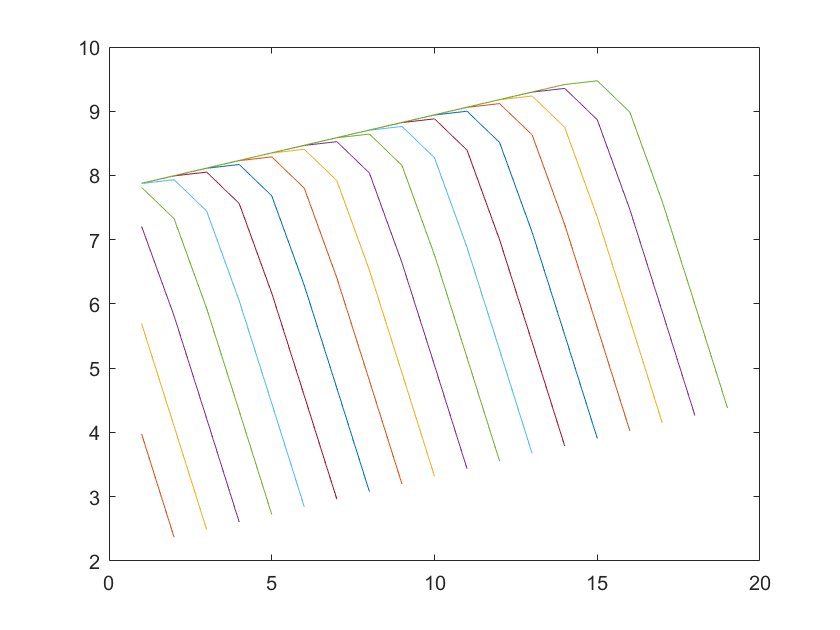

for m = 1:19 
    plot(1:m, dGbox_avr(m, 1:m))
    hold on
end
hold off 

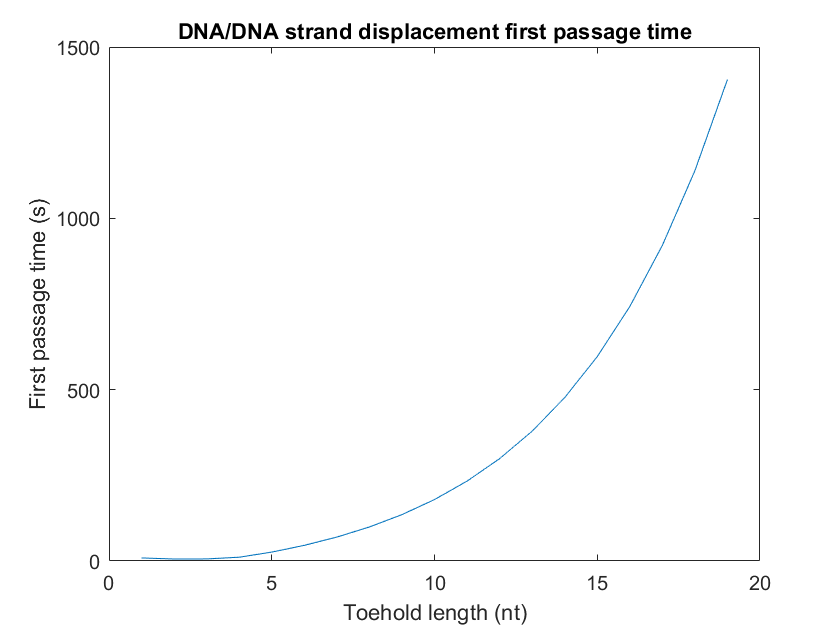


plot(1:19, first_pass_time)
ylabel('First passage time (s)')
xlabel('Toehold length (nt)')
title('DNA/DNA strand displacement first passage time')

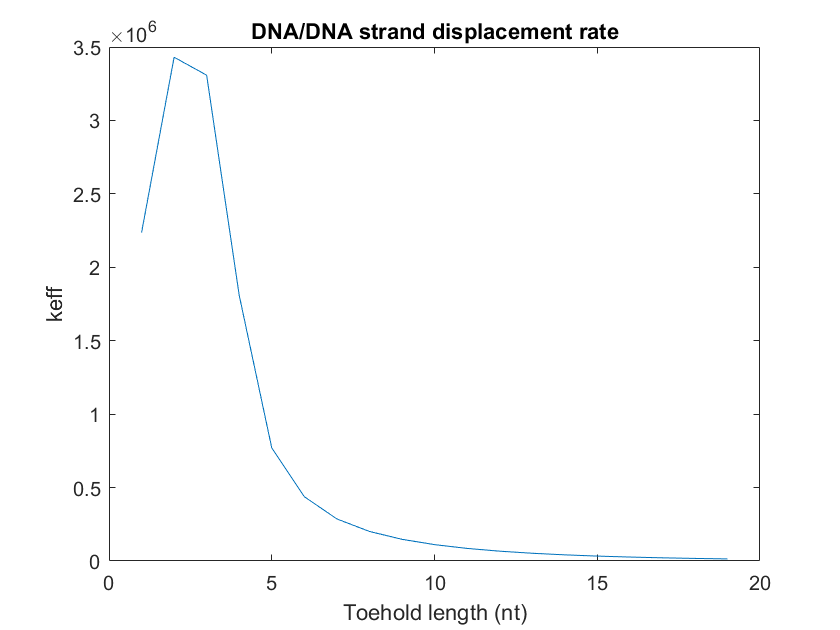


plot(1:19, k_eff)
xlabel('Toehold length (nt)')
ylabel('keff')
title('DNA/DNA strand displacement rate')

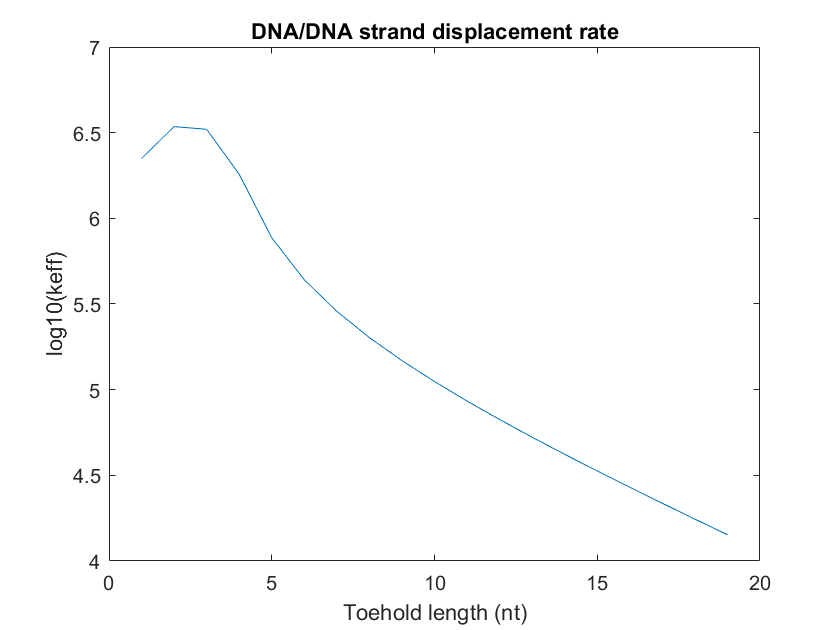


plot(1:19, log10(k_eff))
xlabel('Toehold length (nt)')
ylabel('log10(keff)')
title('DNA/DNA strand displacement rate') 

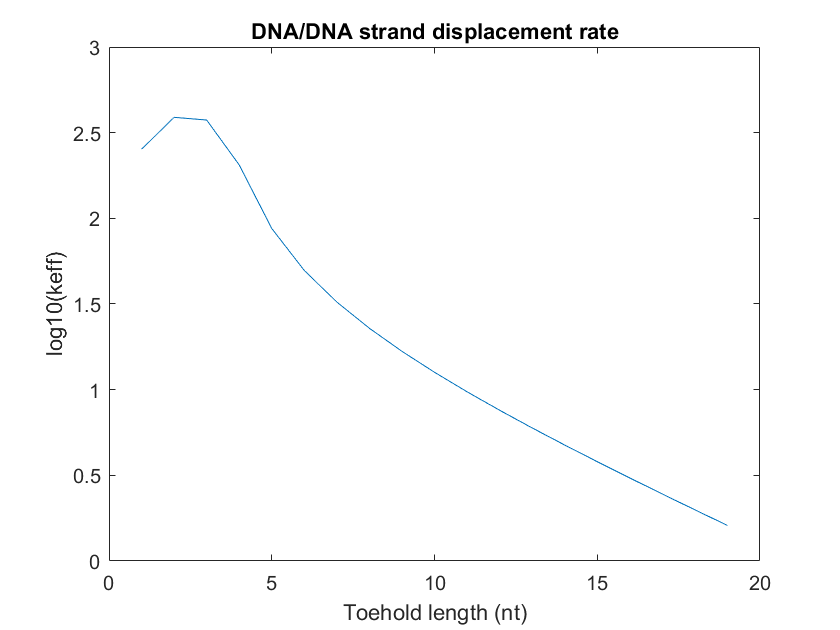


plot(1:19, log10(k_eff./k_eff_perf))
xlabel('Toehold length (nt)')
ylabel('log10(keff)')
title('DNA/DNA strand displacement rate')